# Yapay Zeka Odaklı Karar Mekanizmaları: Derin Öğrenme ile Akıllı Tork Kontrolü

Bu adım adım rehber doküman; **65 kW Çıkık Kutuplu Senkron Motor (Salient-Pole Synchronous Machine)** tork kontrol sisteminin klasik **Lookup Table + PI** mimarisinden, **%100 Yapay Zeka (DNN-1 + DNN-2)** mimarisine nasıl dönüştürüldüğünü **işaretlenmiş Simulink ekran görüntüleri**, hangi kollardan veri çekildiği, hangi blokların silindiği ve yeni ağlara nasıl bağlandığı ile birlikte adım adım açıklamaktadır.

**Live Script Formatına Dönüştürme Notu:**

- MATLAB **Current Folder** panelinde `YapayZeka_TorkKontrolu_AdimAdim_Rehber.m` dosyasına sağ tıklayıp **Open as Live Script** seçeneğine tıklayabilir veya **Editor** sekmesinde **Save As** menüsünden **MATLAB Live Code Files (.mlx)** olarak kaydedebilirsiniz.

- Ayrıca hazır dönüştürülmüş ve çalıştırılmış `YapayZeka_TorkKontrolu_AdimAdim_Rehber.mlx` dosyası da çalışma klasöründe mevcuttur.

## BÖLÜM 0: Sistemin Genel Mimarisi ve Kontrol Döngüleri

Orijinal model (`SMTorqueControl.slx`) ve yapay zeka ile dönüştürülmüş model (`SMTorqueControl_AI.slx`), yüksek gerilimli (350 V DC) bataryadan beslenen bir inverter ve dört bölgeli kıyıcı (four-quadrant chopper) üzerinden sürülen 65 kW gücündeki senkron motordan oluşmaktadır.

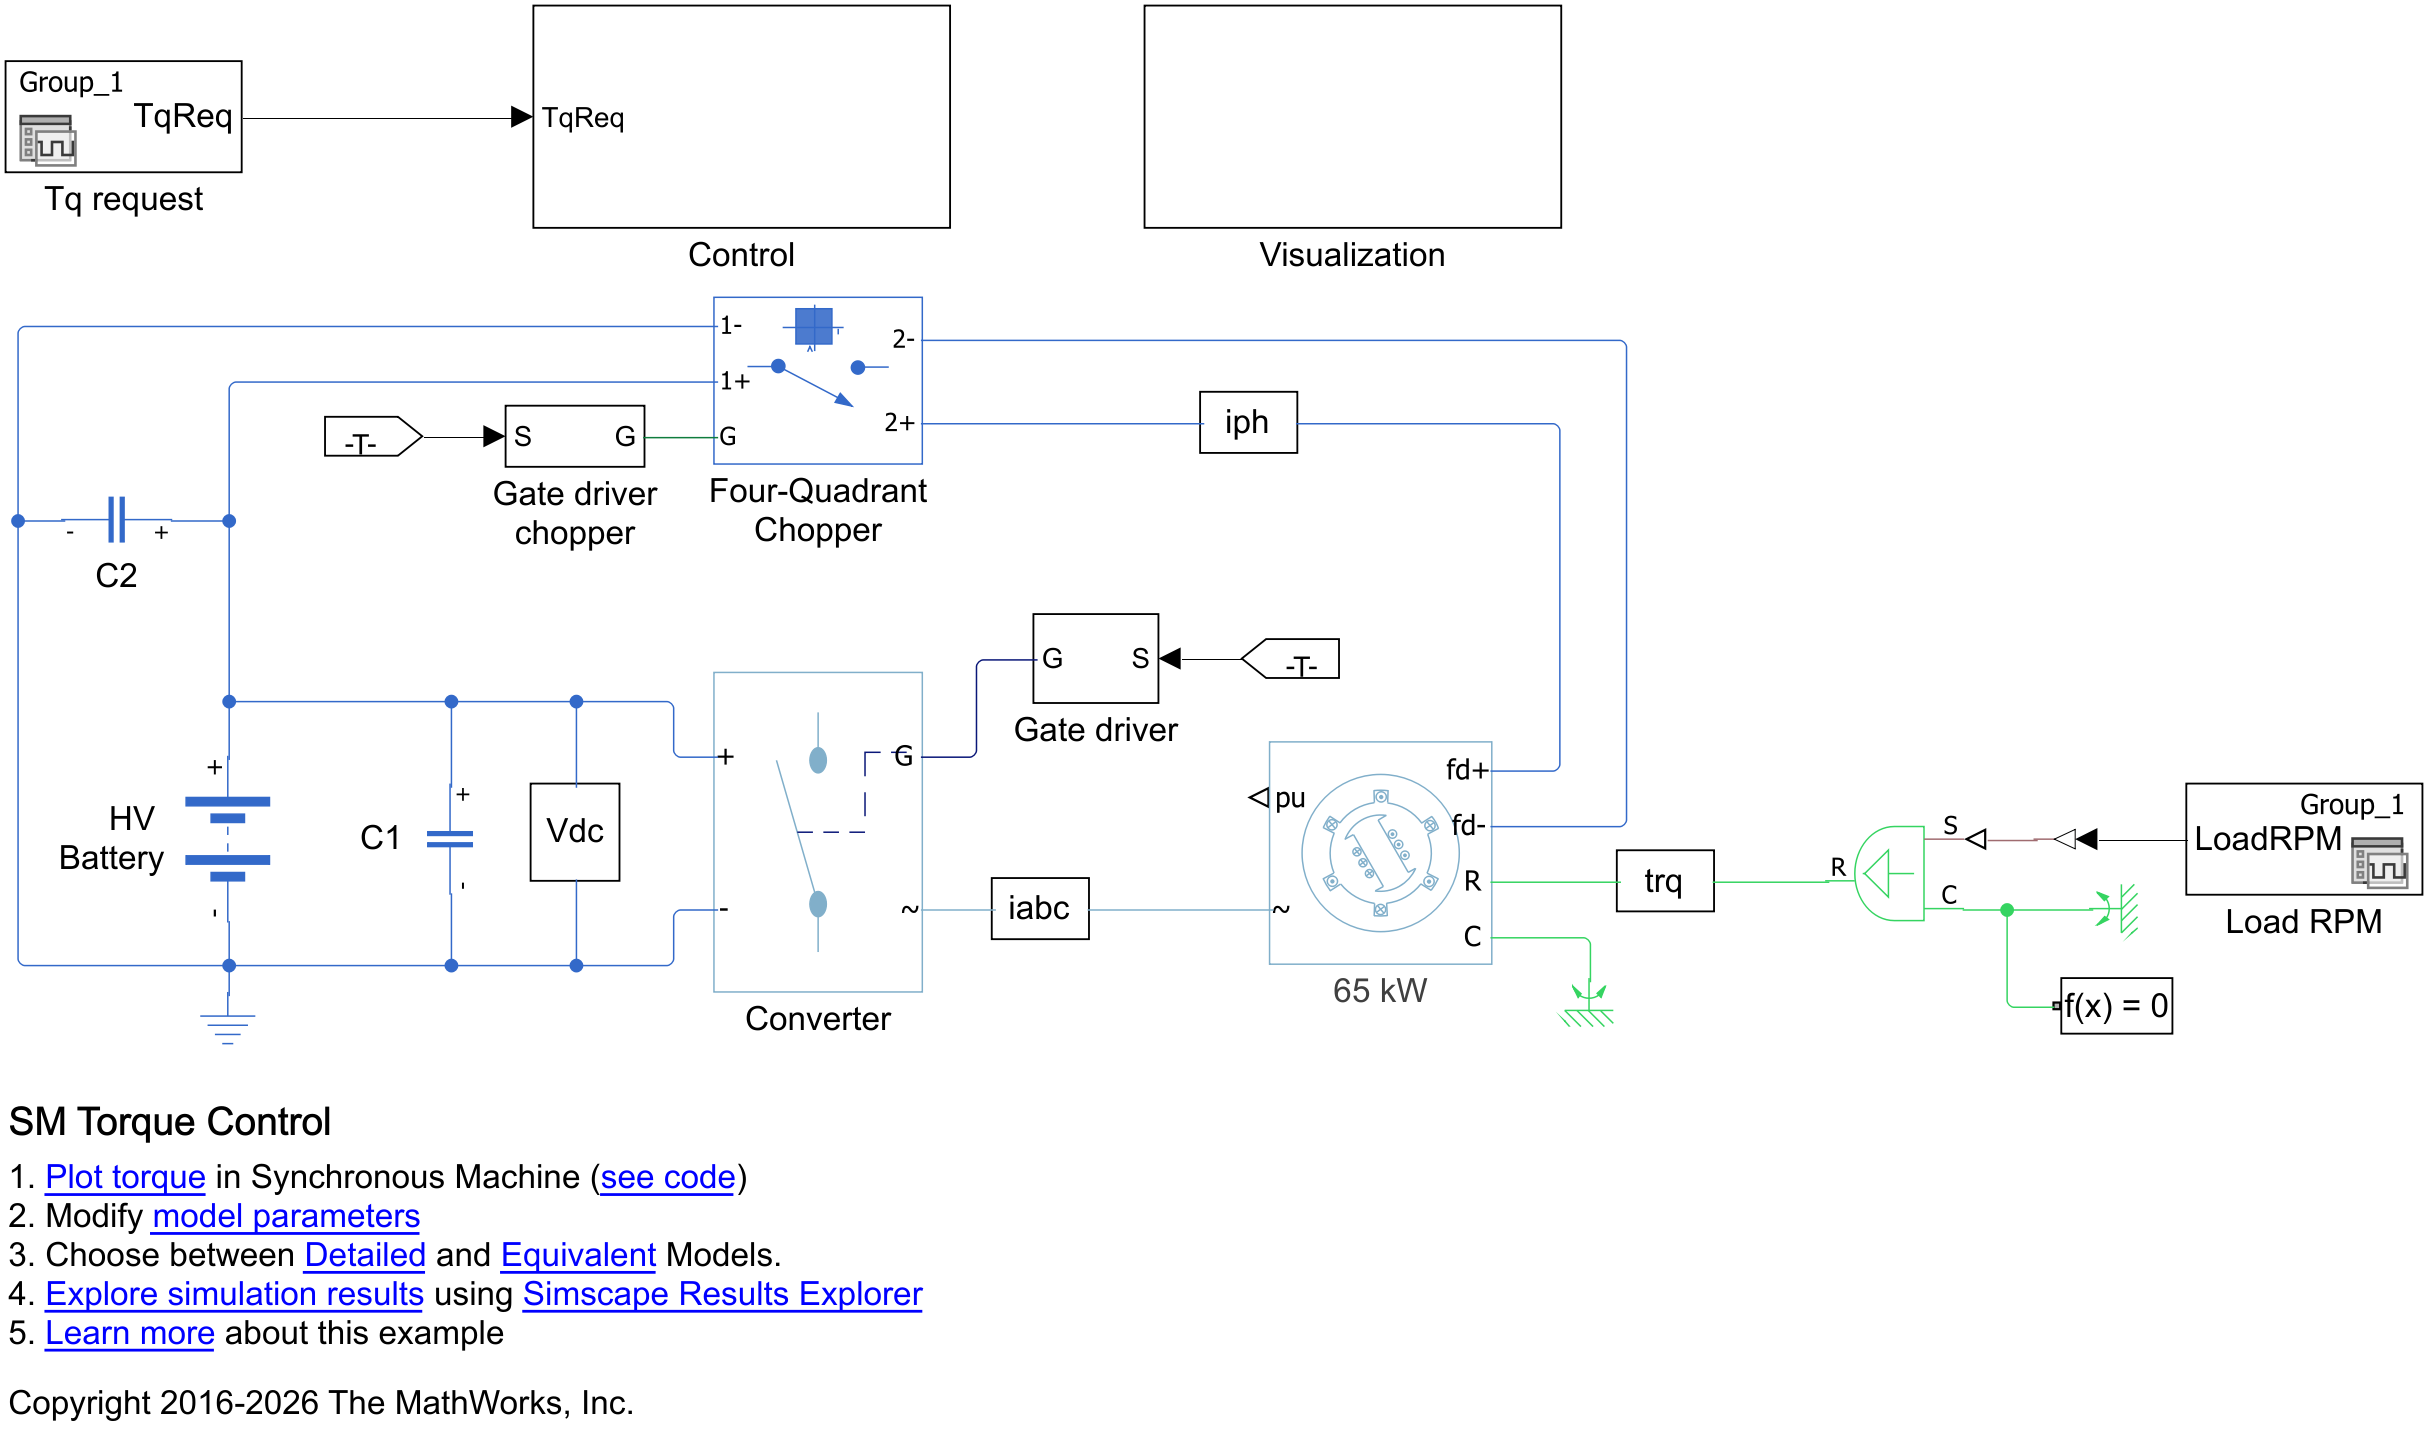

Modelin içerisindeki **Control** alt sistemine girildiğinde aşağıdaki işaretlenmiş görselde görüldüğü gibi iki kademeli (kaskad) bir kontrol yapısı yer alır:

- 1) **Dış Döngü** (`Outer loop control` — Mavi Kutu): $T_s = 1\ \mathrm{ms}$ örnekleme zamanıyla çalışır. `TqReq`, `omega` (Hız) ve `Vdc` kollarını giriş olarak alır. İçindeki klasik 3-Boyutlu Lookup Table blokları silinip yerine **DNN-1 Karar Ağı** (`DNN1_DecisionNet.mat`) yerleştirilir.

- 2) **Ara Bağlantı Kolu** (`[1] idqf_ref` — Yeşil Kol): `DNN-1` ağının ürettiği 3 elemanlı optimum akım referans vektörü (`[id_ref, iq_ref, if_ref]`), doğrudan İç Döngünün 1 numaralı girişine bağlanır.

- 3) **İç Döngü** (`Current control` — Kırmızı Kutu): $T_s = 100\ \mu\mathrm{s}$ örnekleme zamanıyla çalışır. İçindeki 3 adet PI kontrolcü (`PI id`, `Pi iq`, `Pi if`) tamamen silinip yerine **Sadece DNN-2 Kontrol Ağı** (`DNN2_ControllerNet.mat`) yerleştirilir.

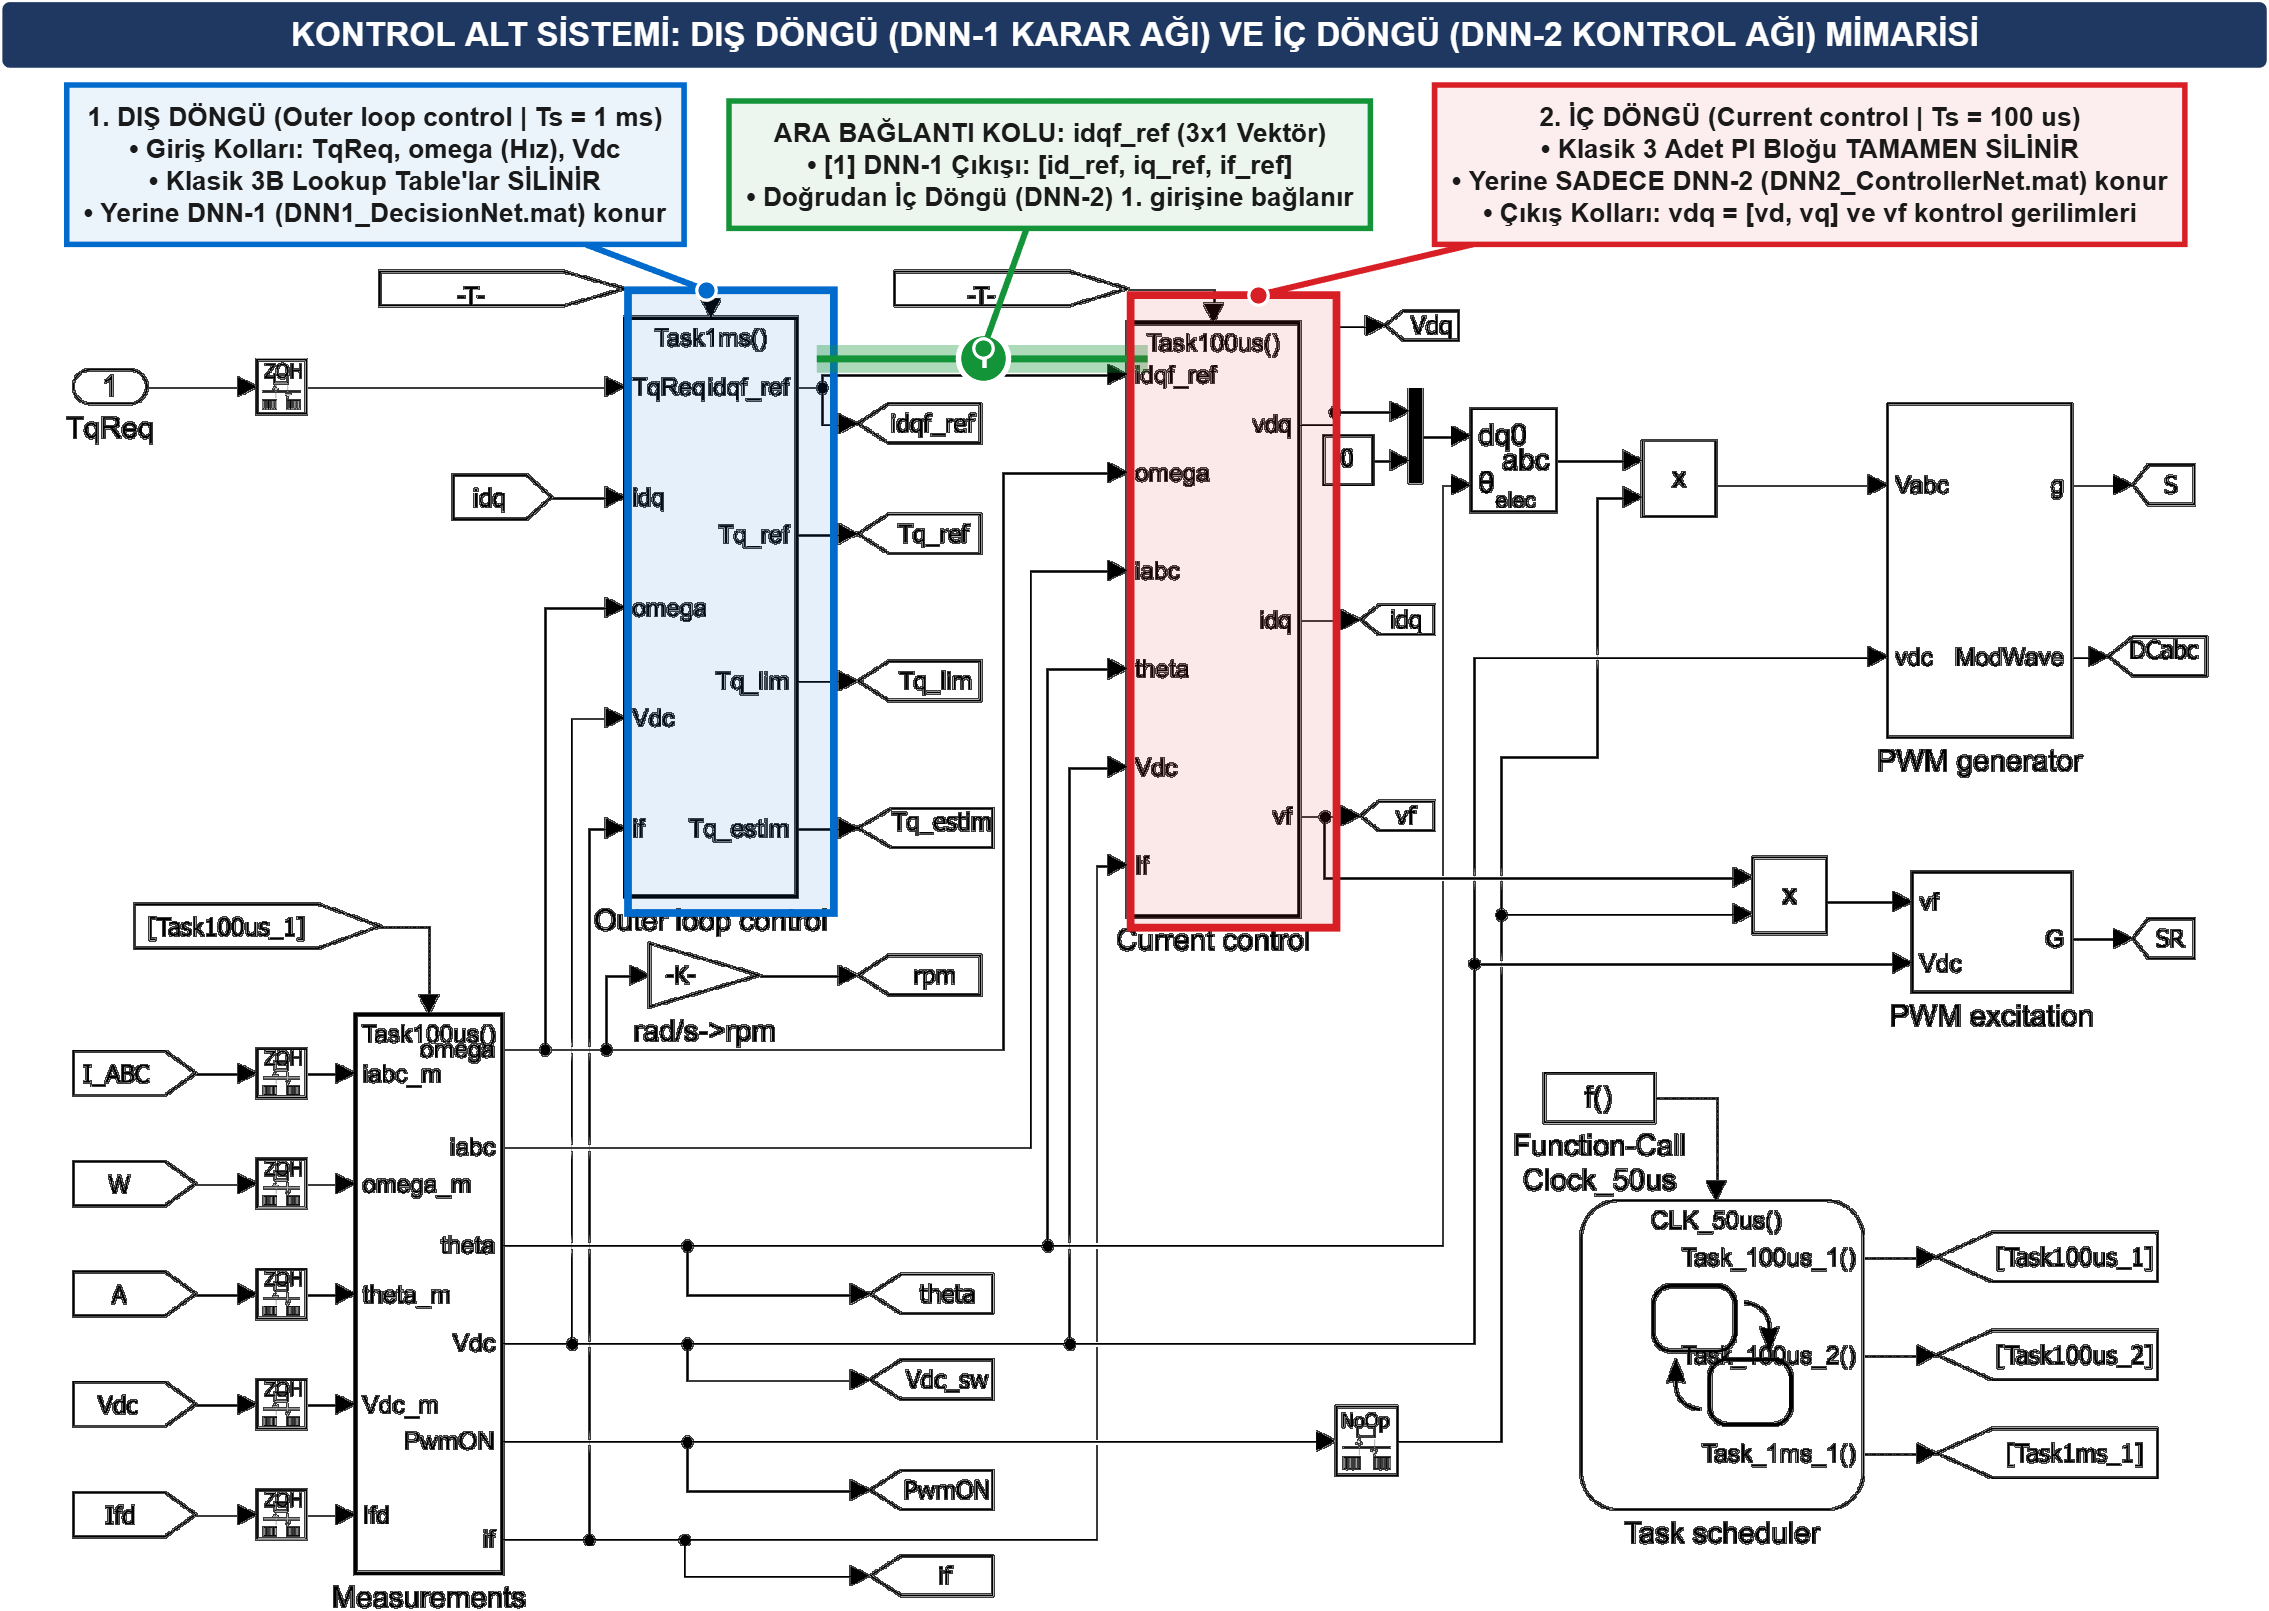

clc; close all;
SMTorqueControlData;

% Not: Ağları sıfırdan tekrar eğitmek yerine kaydedilmiş ağırlıkları hızlıca yüklemek için false bırakın.
Sifirdan_Egit = false;

## BÖLÜM 1 (ADIM 1): Dış Döngü — Yapay Zeka Odaklı Karar Mekanizması (DNN-1)

## 1.1. Klasik Dış Döngüde Hangi Kollardan Veri Alınır ve Hangi Bloklar Silinir? (ÖNCE)

Klasik modelde `Current Reference Generator` alt sistemine girildiğinde aşağıdaki işaretli şemada görülen **Mavi**, **Kırmızı** ve **Yeşil** bölgeler üzerinde işlem yapılır:

**Görsel Üzerindeki Numaralı İşaretlemelerin Açıklaması:**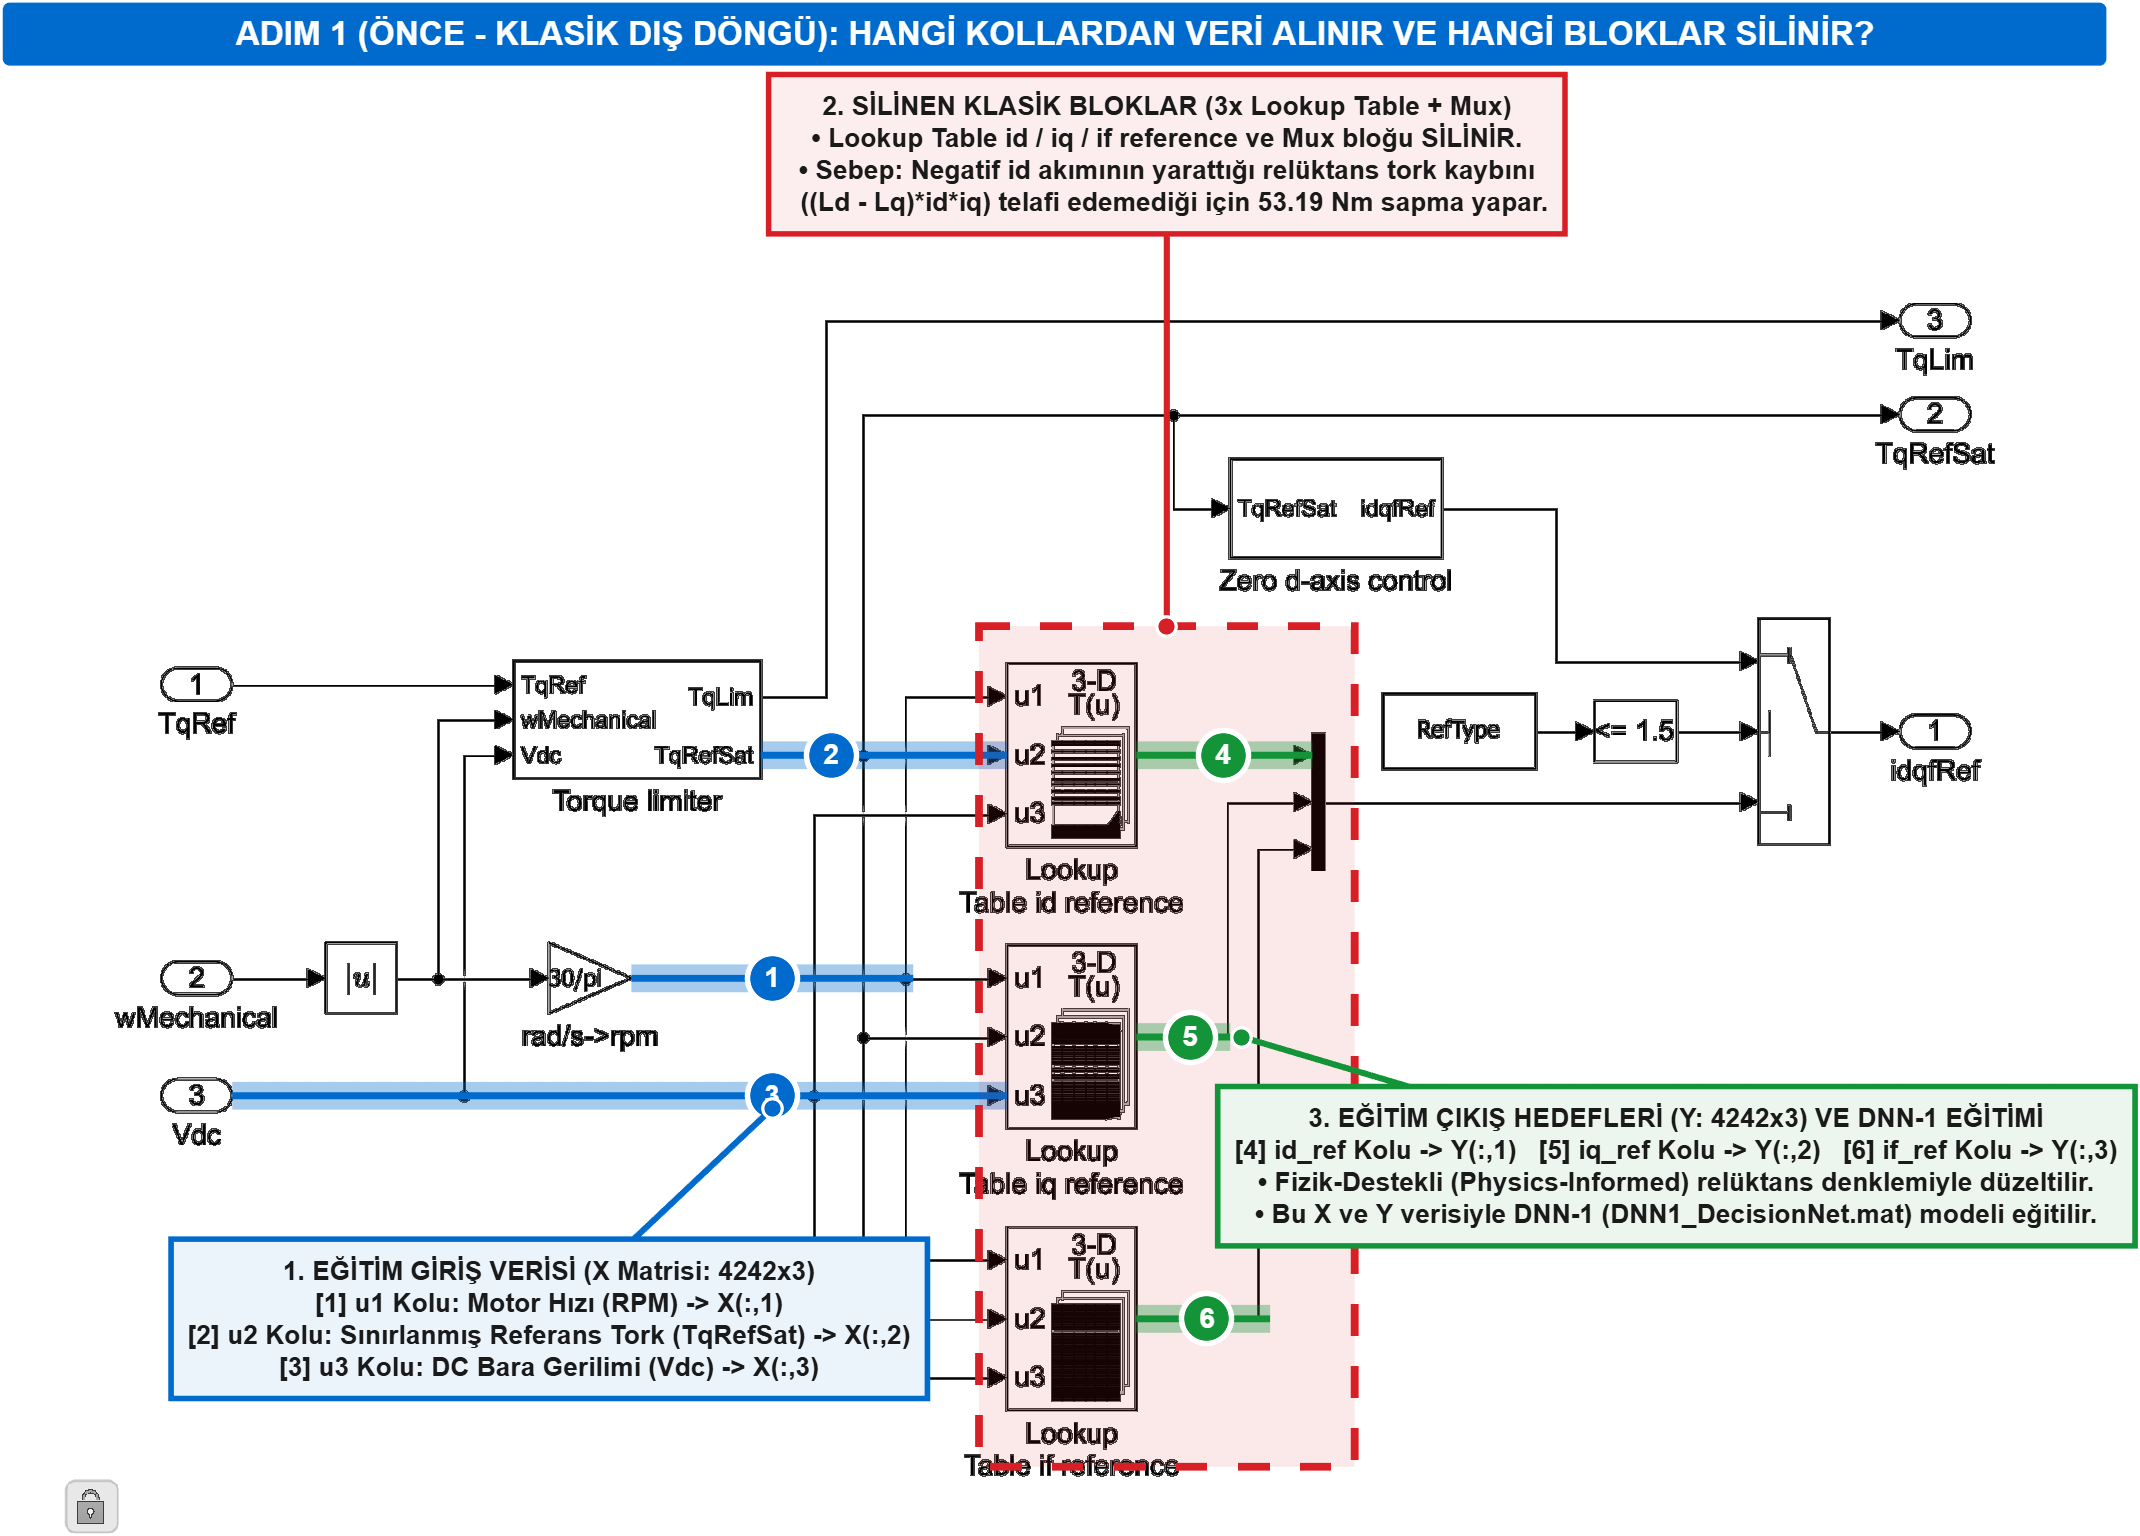

- **[1] Mavi Kol (u1 Girişi):** `rad/s->rpm` kazanç bloğundan çıkan **Motor Hızı** (`RPM`) koludur ve eğitim giriş matrisinin 1. sütununu ($X(:,1)$) oluşturur.

- **[2] Mavi Kol (u2 Girişi):** `Torque limiter` bloğunun 2. çıkışından gelen **Sınırlanmış Referans Tork** (`TqRefSat`) koludur ve giriş matrisinin 2. sütununu ($X(:,2)$) oluşturur.

- **[3] Mavi Kol (u3 Girişi):** 3 numaralı giriş portundan gelen **DC Bara Gerilimi** (`Vdc`) koludur ve giriş matrisinin 3. sütununu ($X(:,3)$) oluşturur.

- **Kırmızı Kesikli Kutu (Silinen Klasik Bloklar):** `Lookup Table id reference`, `Lookup Table iq reference`, `Lookup Table if reference` ve çıkışlarındaki `Mux` bloğu modelden tamamen **silinir**. Çıkık kutuplu senkron makinede $L_d = 1.05\ \mathrm{pu} > L_q = 0.70\ \mathrm{pu}$ olduğundan elektromanyetik tork denklemi $T_e = \left(i_f + (L_d - L_q) i_d\right) i_q$ şeklindedir. Orijinal tablolar negatif $i_d$ akımının yarattığı relüktans tork kaybını ($(L_d - L_q)i_d i_q$) telafi etmediği için klasik kontrolde **53.19 Nm** kalıcı tork sapması oluşmaktadır.

- **[4], [5], [6] Yeşil Kollar (Hedef Çıkışlar):** Tablo çıkışlarındaki `id_ref` ($Y(:,1)$), `iq_ref` ($Y(:,2)$) ve `if_ref` ($Y(:,3)$) kollarıdır. Bu 3 koldaki referans akım haritaları fizik-destekli relüktans denklemiyle düzeltilerek **DNN-1** (`DNN1_DecisionNet.mat`) modeli eğitilir.

## 1.2. 3-Boyutlu Optimum Akım Haritalarının İncelenmesi ve Fizik-Destekli Veri Üretimi

Aşağıdaki kod bloğu, motorun çalışma uzayındaki ($7 \times 101 \times 6 = 4242$ çalışma noktası) referans akım yüzeylerini görselleştirir ve relüktans tork kaybını telafi eden **Fizik-Destekli (Physics-Informed)** eğitim veri setini ($X \in \mathbb{R}^{4242 \times 3}$, $Y \in \mathbb{R}^{4242 \times 3}$) hazırlar.

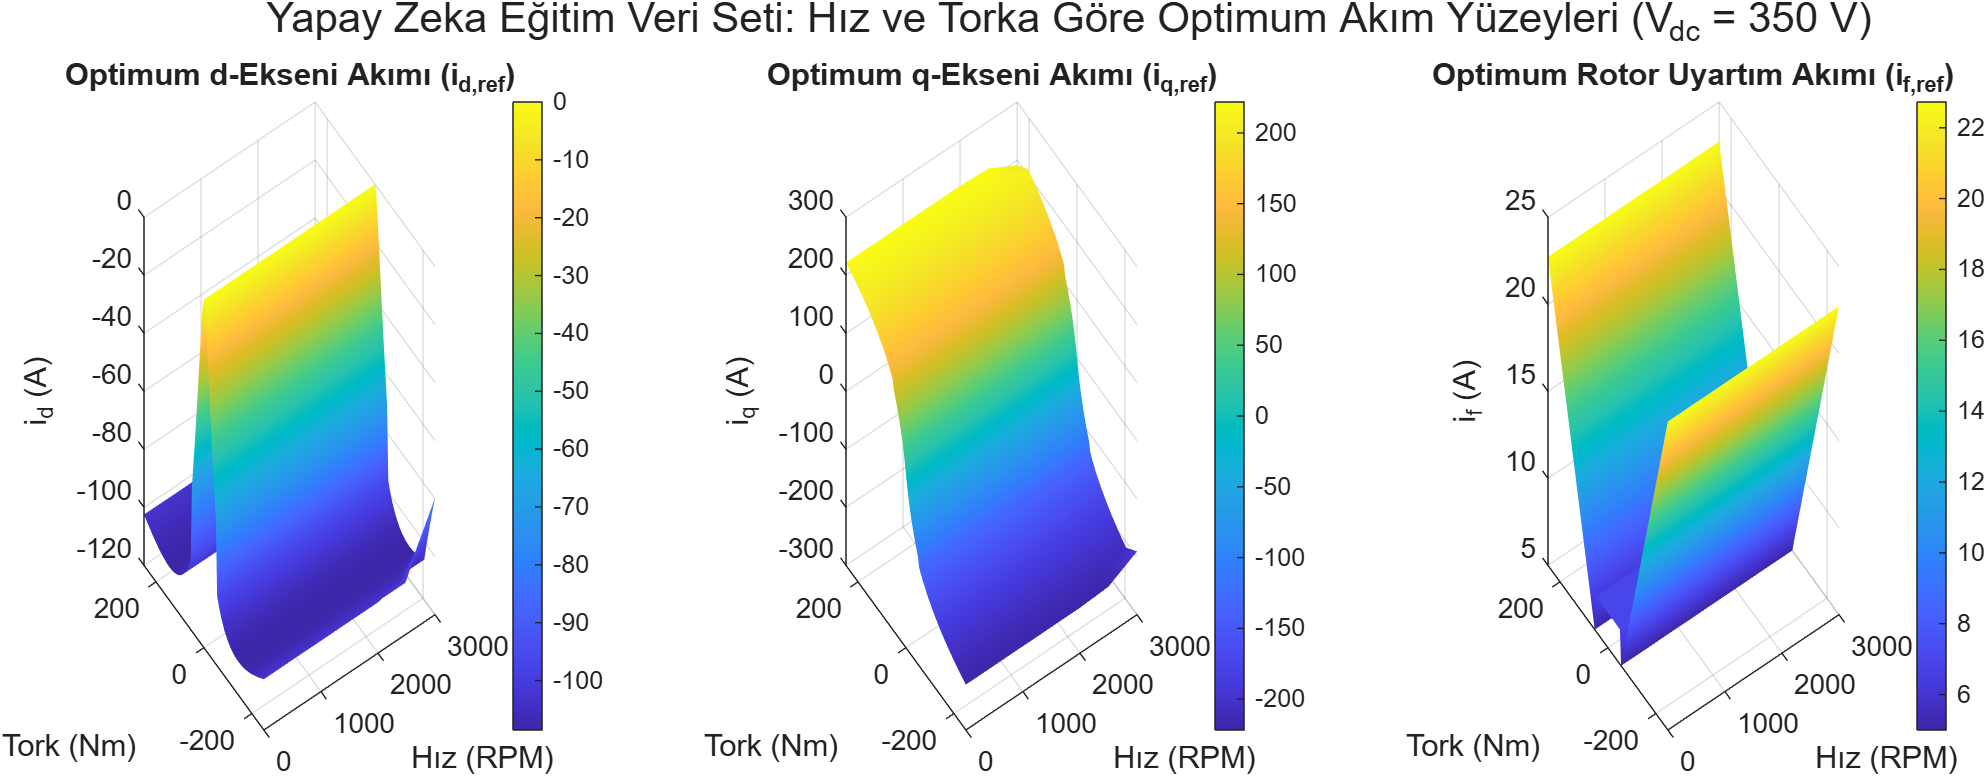

% 3B Optimum Akım Haritalarını Çizdir (Vdc = 350 V)
vdc_idx = 4;
[TQ_GRID, RPM_GRID] = meshgrid(TQ_VECT, RPM_VECT);

% 3B ızgarayı ve Fizik-Destekli (Physics-Informed) akım hedeflerini oluştur
[RPM_3D, TQ_3D, VDC_3D] = ndgrid(RPM_VECT, TQ_VECT, VDC_VECT);

psi_d_target = (IF_MAP / Ifbase) - (Ld - Lq) * (ID_MAP / Ibase);
ID_PHYS      = 0.15 * ID_MAP;
IF_PHYS      = min(max(Ifbase * (psi_d_target - (Ld - Lq) * (ID_PHYS / Ibase)), 5), 25);
psi_d_actual = (IF_PHYS / Ifbase) + (Ld - Lq) * (ID_PHYS / Ibase);
IQ_PHYS      = min(max(Ibase * (TQ_3D ./ Tbase) ./ psi_d_actual, -235), 235);

% Giriş X: [RPM, Tq_ref, Vdc] (4242 x 3) | Çıkış Y: [id_ref, iq_ref, if_ref] (4242 x 3)
X = [RPM_3D(:), TQ_3D(:), VDC_3D(:)];
Y = [ID_PHYS(:), IQ_PHYS(:), IF_PHYS(:)];

muY  = mean(Y, 1);
sigY = std(Y, 0, 1);
Y_norm = (Y - muY) ./ sigY;

rng(42);
N = size(X, 1);
idx = randperm(N);
nTrain = round(0.85 * N);

XTrain = X(idx(1:nTrain), :);
YTrain = Y_norm(idx(1:nTrain), :);
XVal   = X(idx(nTrain+1:end), :);
YVal   = Y_norm(idx(nTrain+1:end), :);

## 1.3. DNN-1 Karar Ağı Mimarisi (3 -> 64 -> 64 -> 32 -> 3) ve Eğitimi

Dış döngü karar mekanizması için tasarlanan ileri beslemeli derin sinir ağı (`net_decision`):

- 1) **Giriş Katmanı** (`Giris`): 3 özellik (`[RPM, Tq_ref, Vdc]`), `zscore` normalizasyonlu

- 2) **Gizli Katman 1:** 64 nöron (`fullyConnectedLayer`) + `tanhLayer`

- 3) **Gizli Katman 2:** 64 nöron (`fullyConnectedLayer`) + `reluLayer`

- 4) **Gizli Katman 3:** 32 nöron (`fullyConnectedLayer`) + `reluLayer`

- 5) **Çıkış Katmanı** (`Cikis`): 3 çıkış (`[id_ref, iq_ref, if_ref]`), denormalizasyon ağırlıkları gömülü

layers_dnn1 = [
    featureInputLayer(3, 'Name', 'Giris', ...
        'Normalization', 'zscore', ...
        'Mean', mean(XTrain, 1), ...
        'StandardDeviation', std(XTrain, 0, 1))
    fullyConnectedLayer(64, 'Name', 'FC_Katman1')
    tanhLayer('Name', 'Aktivasyon1_Tanh')
    fullyConnectedLayer(64, 'Name', 'FC_Katman2')
    reluLayer('Name', 'Aktivasyon2_ReLU')
    fullyConnectedLayer(32, 'Name', 'FC_Katman3')
    reluLayer('Name', 'Aktivasyon3_ReLU')
    fullyConnectedLayer(3,  'Name', 'Cikis')
];

if Sifirdan_Egit
    options1 = trainingOptions('adam', ...
        'MaxEpochs', 300, ...
        'MiniBatchSize', 128, ...
        'InitialLearnRate', 0.005, ...
        'LearnRateSchedule', 'piecewise', ...
        'LearnRateDropFactor', 0.5, ...
        'LearnRateDropPeriod', 100, ...
        'L2Regularization', 1e-4, ...
        'ValidationData', {XVal, YVal}, ...
        'ValidationFrequency', 30, ...
        'ValidationPatience', 15, ...
        'OutputNetwork', 'best-validation', ...
        'Shuffle', 'every-epoch', ...
        'Plots', 'training-progress', ...
        'Verbose', false);
    net_norm = trainnet(XTrain, YTrain, layers_dnn1, 'mse', options1);
    lastLayer = net_norm.Layers(end);
    lastLayer.Weights = lastLayer.Weights .* sigY';
    lastLayer.Bias    = lastLayer.Bias .* sigY' + muY';
    net_decision = dlnetwork(replaceLayer(layerGraph(net_norm), lastLayer.Name, lastLayer));
    save('DNN1_DecisionNet.mat', 'net_decision');
else
    load('DNN1_DecisionNet.mat', 'net_decision');
    disp('DNN-1 (net_decision) hazir model dosyasindan (DNN1_DecisionNet.mat) yuklendi.');
end

DNN-1 (net_decision) hazir model dosyasindan (DNN1_DecisionNet.mat) yuklendi.


## 1.4. DNN-1 Karar Ağı Doğrulama (Validation) Başarısı

Eğitilen `DNN-1` ağının tahminleri gerçek fizik-destekli optimum akım referanslarıyla karşılaştırıldığında tüm eksenlerde $R^2 > 0.999$ doğruluk elde edilmiştir:

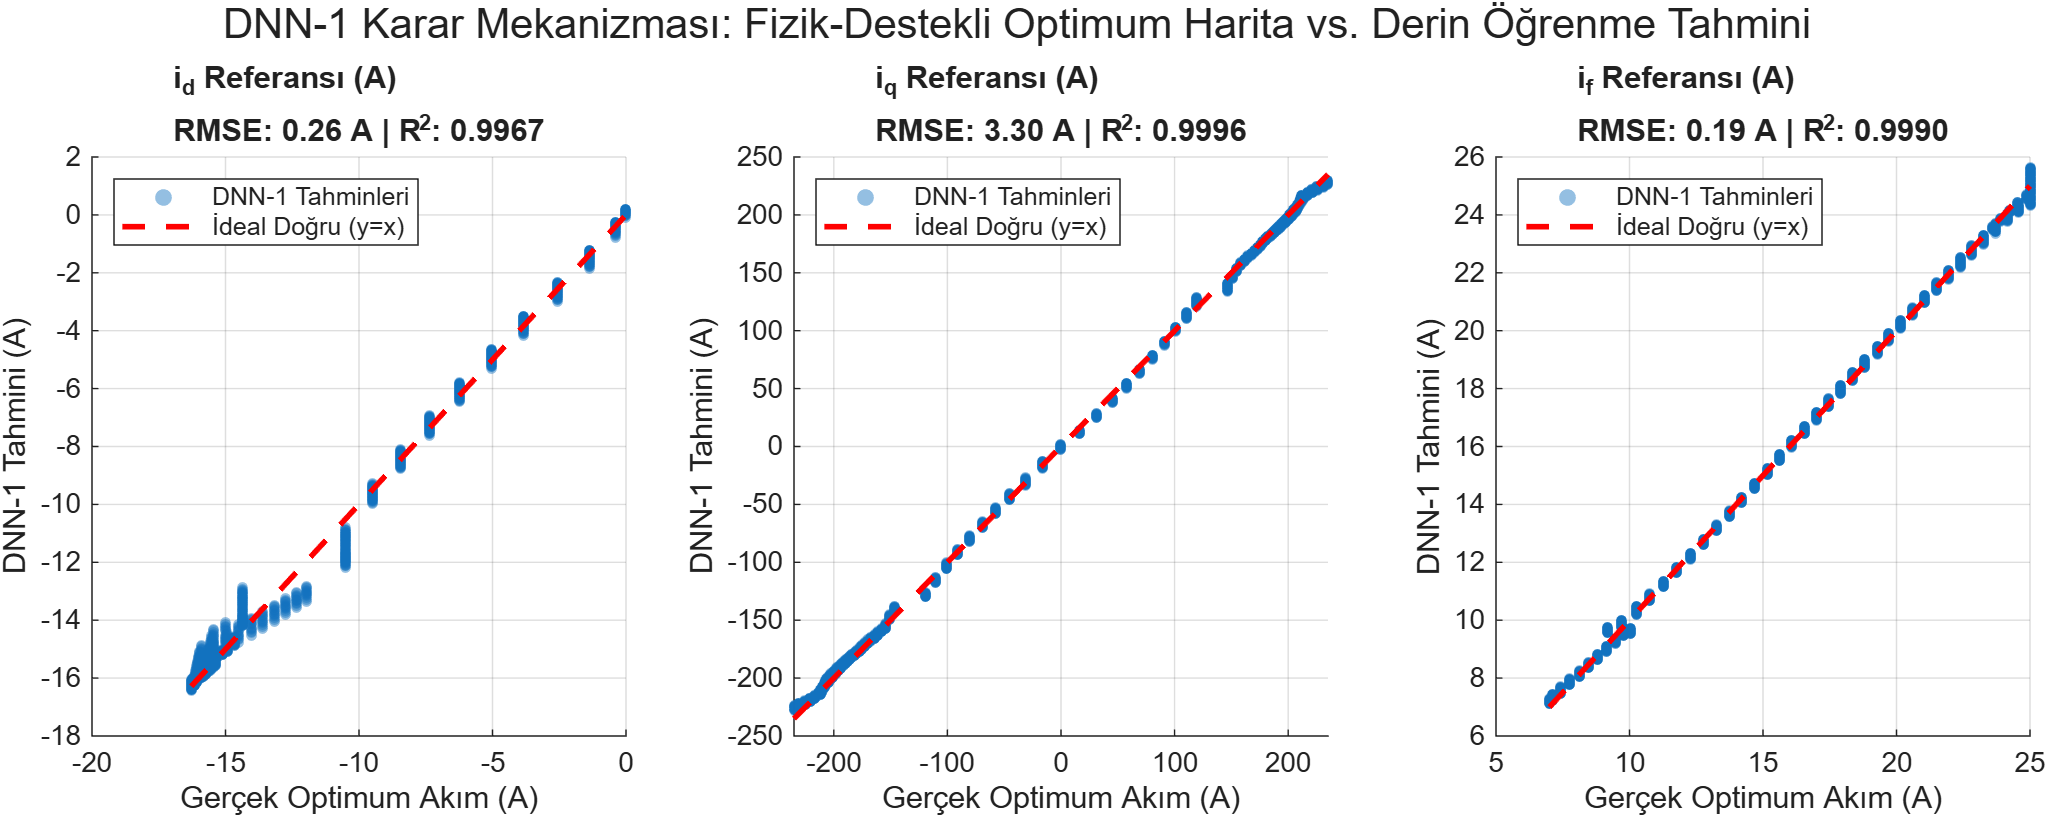

YPred_Val = double(predict(net_decision, XVal));
YTrue_Val = Y(idx(nTrain+1:end), :);

## 1.5. Simulink Dış Döngüsünde Kolların DNN-1 Karar Ağına Bağlanması (SONRA)

3 adet Lookup Table silindikten sonra kolların `DNN1_Karar_Agi` bloğuna nasıl bağlandığı aşağıdaki işaretlenmiş şema üzerinde numaralı olarak gösterilmiştir:

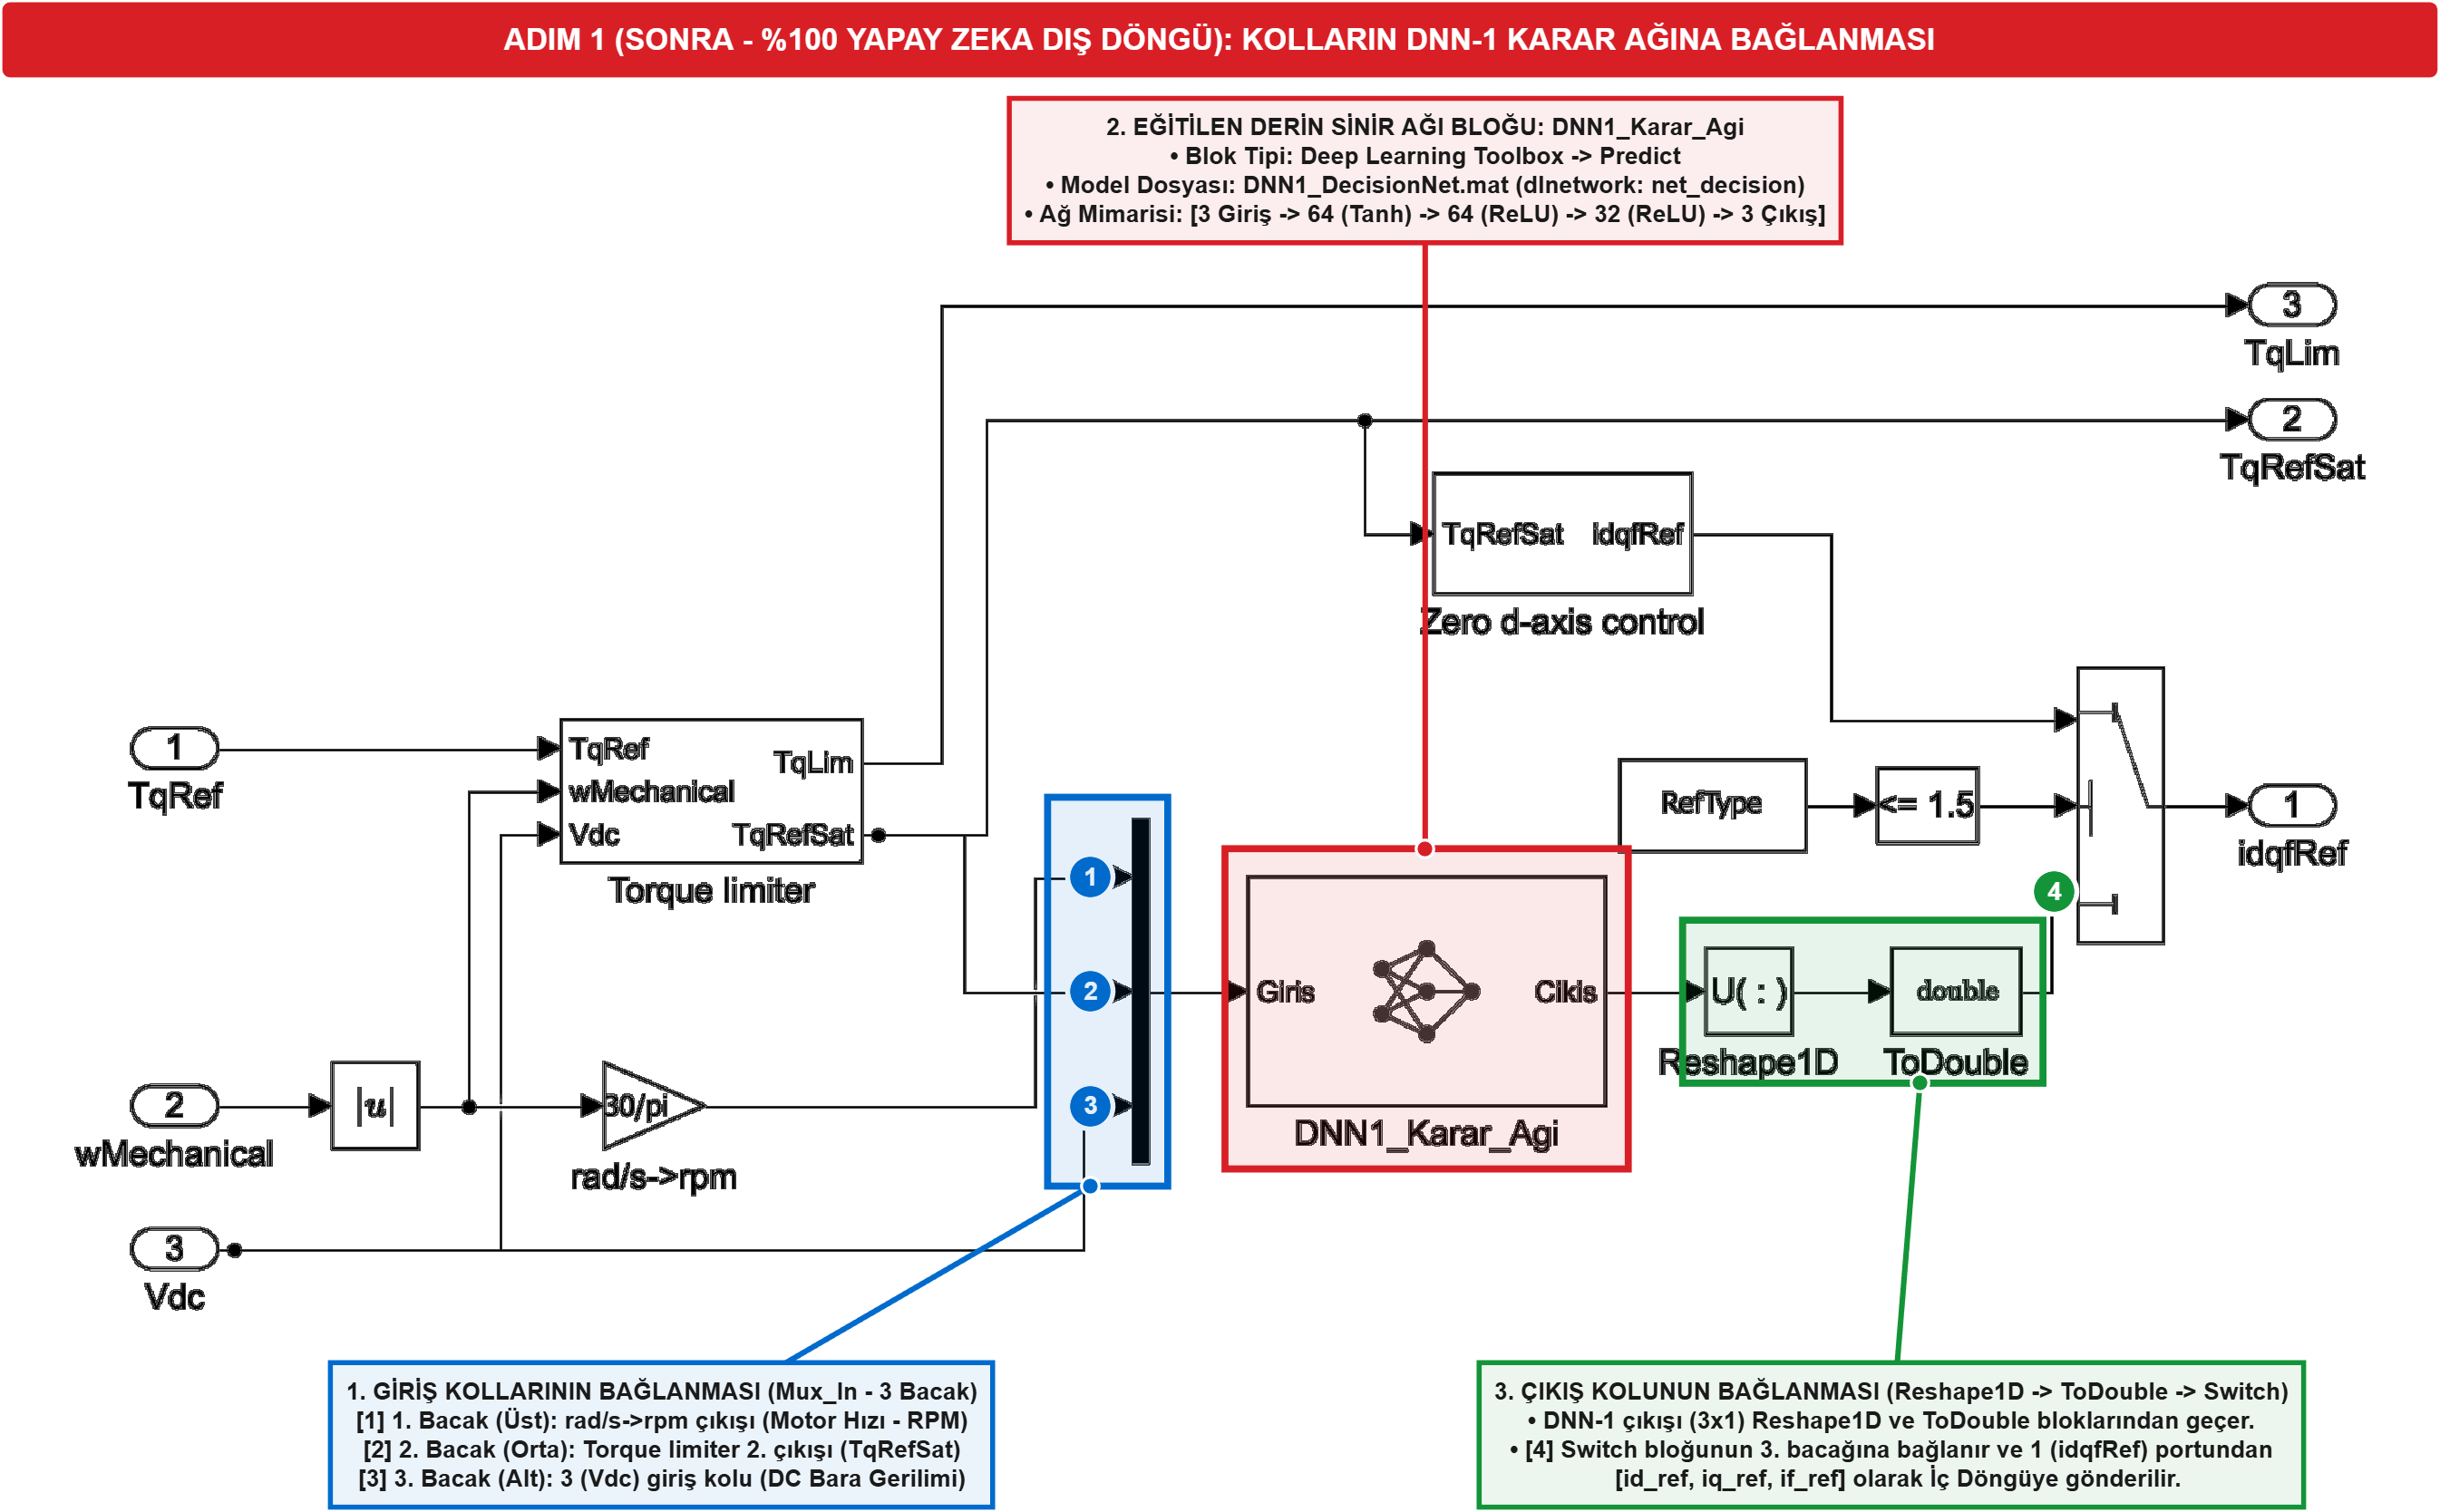

**Dış Döngü Bağlantı Adımları:**

- **[1] Mux_In 1. Bacak (Üst Kol):** `rad/s->rpm` bloğunun çıkışı olan **Motor Hızı** (`RPM`) bağlanır.

- **[2] Mux_In 2. Bacak (Orta Kol):** `Torque limiter` bloğunun 2. çıkışı olan **Sınırlanmış Referans Tork** (`TqRefSat`) bağlanır.

- **[3] Mux_In 3. Bacak (Alt Kol):** `3 (Vdc)` giriş portu olan **DC Bara Gerilimi** bağlanır.

- **Kırmızı Kutu (DNN1_Karar_Agi):** `Mux_In` çıkışı (`3x1`), `DNN1_DecisionNet.mat` dosyasını kullanan `Predict` bloğunun `Giris` portuna bağlanır.

- **[4] Yeşil Kutu (Reshape1D -> ToDouble -> Switch):** `DNN1_Karar_Agi` `Cikis` portundan alınan `[id_ref, iq_ref, if_ref]` vektörü `Reshape1D` ve `ToDouble` bloklarından geçirilerek `[4]` numaralı noktadan `Switch` bloğunun 3. bacağına bağlanır ve `1 (idqfRef)` çıkış portundan İç Döngüye gönderilir.

## BÖLÜM 2 (ADIM 2): İç Döngü — PI Blokları Yerine Sadece Yapay Zeka Kontrolcüsü (DNN-2)

## 2.1. Klasik İç Döngüde Hangi Kollardan Eğitim Verisi Çekilir ve Hangi PI Blokları Silinir? (ÖNCE)

İç döngüdeki (`SM Current Controller`) 3 adet PI kontrolcüyü tamamen kaldırıp yerine tek bir MIMO Derin Sinir Ağı (`DNN-2`) koymak için önce klasik modelde aşağıdaki işaretli kollardan `DataLogging` ile simülasyon verisi (10.001 zaman adımı, $T_s = 100\ \mu\mathrm{s}$) çekilir:

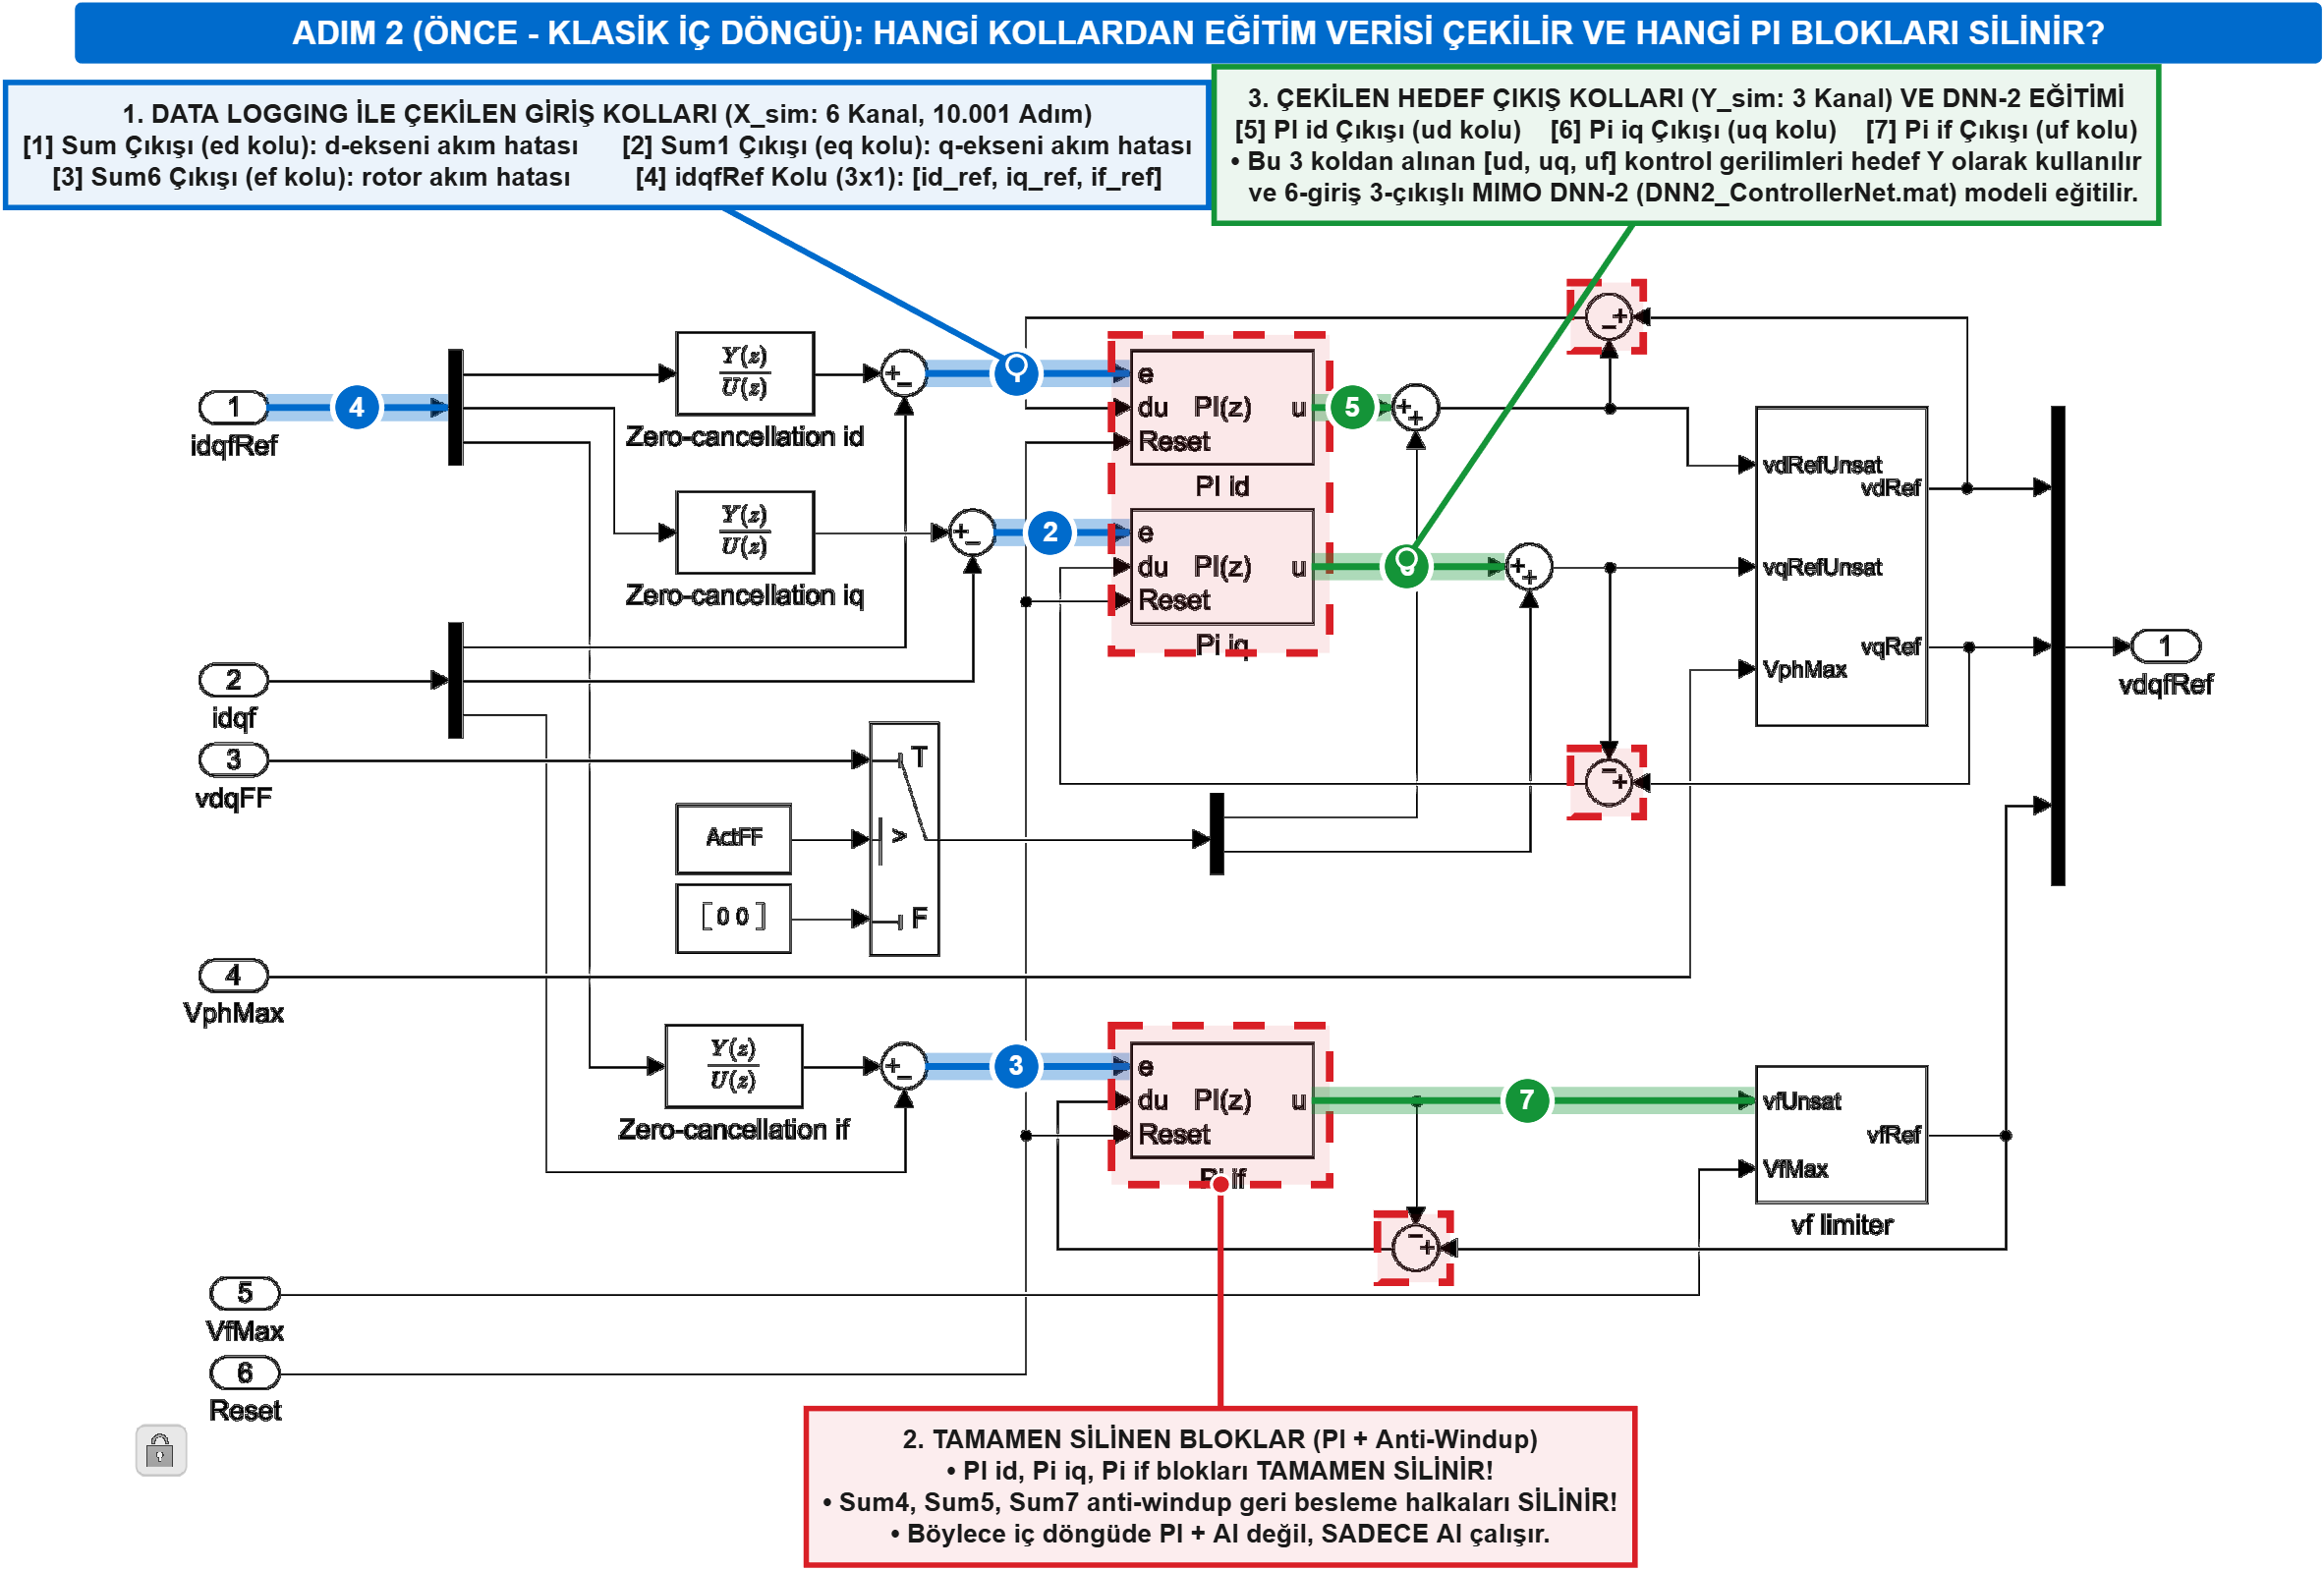

**Görsel Üzerindeki Numaralı İşaretlemelerin Açıklaması:**

- **[1] Mavi Kol (ed Hatası):** `Sum` bloğu çıkışından (`PI id` bloğunun `e` girişi) **d-ekseni akım hatası** ($e_d = i_{d,\mathrm{ref}} - i_d$) çekilir.

- **[2] Mavi Kol (eq Hatası):** `Sum1` bloğu çıkışından (`Pi iq` bloğunun `e` girişi) **q-ekseni akım hatası** ($e_q = i_{q,\mathrm{ref}} - i_q$) çekilir.

- **[3] Mavi Kol (ef Hatası):** `Sum6` bloğu çıkışından (`Pi if` bloğunun `e` girişi) **rotor akım hatası** ($e_f = i_{f,\mathrm{ref}} - i_f$) çekilir.

- **[4] Mavi Kol (idqfRef Vektörü):** `1 (idqfRef)` ana giriş kolundan **3 elemanlı referans akım vektörü** (`[id_ref, iq_ref, if_ref]`) çekilir. Böylece toplam 6 giriş kanalı ($X_{\mathrm{sim}}$) elde edilir.

- **Kırmızı Kesikli Kutular (Tamamen Silinen PI ve Anti-Windup Blokları):** `PI id`, `Pi iq`, `Pi if` kontrolcü blokları ve `Sum4`, `Sum5`, `Sum7` anti-windup geri besleme toplamaları modelden **tamamen silinir**. Böylece iç döngüde PI + AI değil, **SADECE AI** çalışır.

- **[5], [6], [7] Yeşil Kollar (Çekilen Hedef Gerilim Çıkışları):** `PI id` çıkışından **d-ekseni kontrol gerilimi** ($u_d$), `Pi iq` çıkışından **q-ekseni kontrol gerilimi** ($u_q$) ve `Pi if` çıkışından **rotor kontrol gerilimi** ($u_f$) çekilir. Bu 6 giriş ($X_{\mathrm{sim}}$) ve 3 çıkış ($Y_{\mathrm{sim}}$) kullanılarak **DNN-2** (`DNN2_ControllerNet.mat`) modeli eğitilir.

## 2.2. İç Döngü Eğitim Verisinin İncelenmesi ve Durum Uzayı Zenginleştirmesi

Simülasyondan çekilen $[e_d, e_q, e_f]$ hataları ve $[u_d, u_q, u_f]$ kontrol gerilimleri aşağıda görselleştirilmiştir:

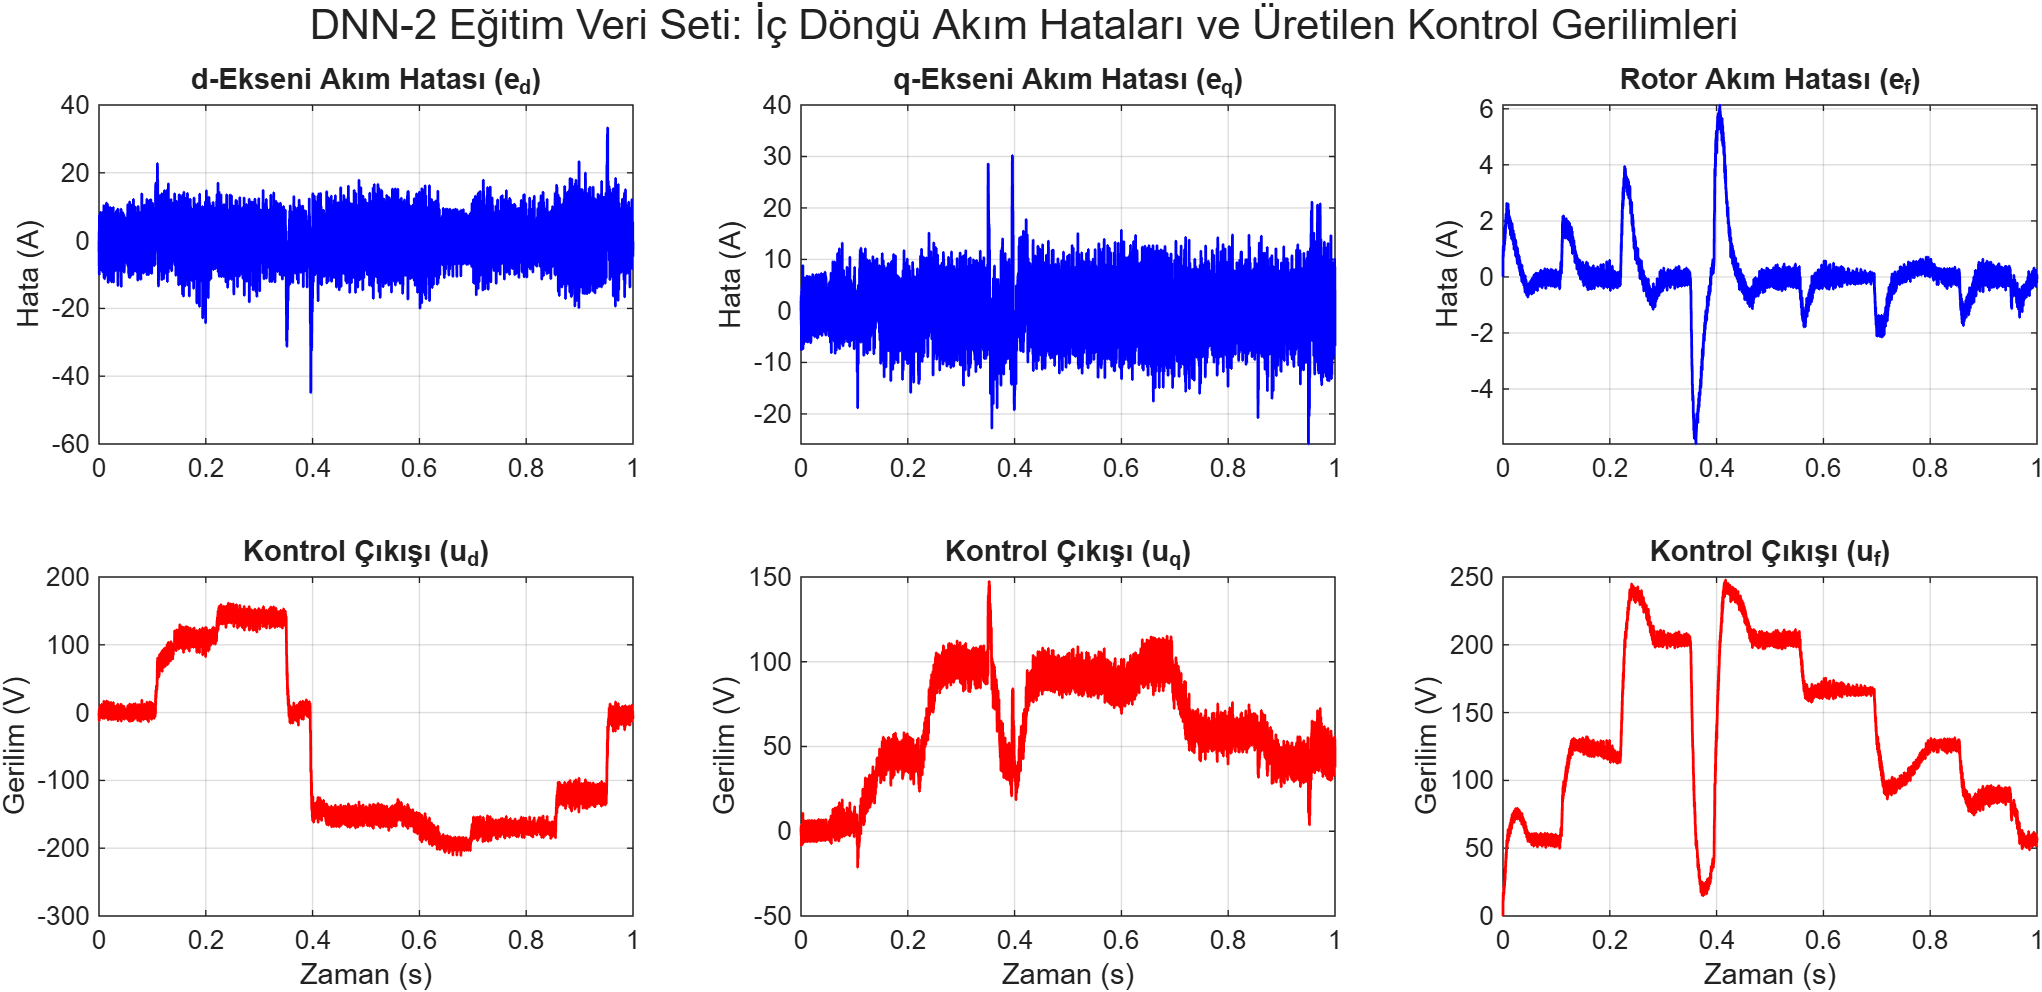

load('DNN2_Training_Data.mat', 't_sim', 'ed', 'eq', 'ef', 'iref_d', 'ud', 'uq', 'uf');

% Durum uzayı zenginleştirmesi (Data Augmentation - 15.000 ek çalışma noktası)
xId_ss = ud - Kp_id * ed;
xIq_ss = uq - Kp_iq * eq;
xIf_ss = uf - Kp_if * ef;

rng(42);
N_aug    = 15000;
idx_base = randi(length(t_sim), N_aug, 1);
ed_aug   = (rand(N_aug,1)*2 - 1) * max(abs(ed))*1.2;
eq_aug   = (rand(N_aug,1)*2 - 1) * max(abs(eq))*1.2;
ef_aug   = (rand(N_aug,1)*2 - 1) * max(abs(ef))*1.2;

id_r_aug = iref_d(idx_base,1) + randn(N_aug,1)*0.5;
iq_r_aug = iref_d(idx_base,2) + randn(N_aug,1)*1.0;
if_r_aug = iref_d(idx_base,3) + randn(N_aug,1)*0.2;

ud_aug = xId_ss(idx_base) + Kp_id * ed_aug;
uq_aug = xIq_ss(idx_base) + Kp_iq * eq_aug;
uf_aug = xIf_ss(idx_base) + Kp_if * ef_aug;

% 6 Giriş: [ed, eq, ef, id_ref, iq_ref, if_ref] -> 3 Çıkış: [ud, uq, uf]
X_sim = [ed, eq, ef, iref_d];
Y_sim = [ud, uq, uf];

X_all = [X_sim; [ed_aug, eq_aug, ef_aug, id_r_aug, iq_r_aug, if_r_aug]];
Y_all = [Y_sim; [ud_aug, uq_aug, uf_aug]];

muY2  = mean(Y_all, 1);
sigY2 = std(Y_all, 0, 1);
Y_all_norm = (Y_all - muY2) ./ sigY2;

N_total = size(X_all, 1);
idx2 = randperm(N_total);
nTr2 = round(0.85 * N_total);

XTrain2 = X_all(idx2(1:nTr2), :);
YTrain2 = Y_all_norm(idx2(1:nTr2), :);
XVal2   = X_all(idx2(nTr2+1:end), :);
YVal2   = Y_all_norm(idx2(nTr2+1:end), :);

## 2.3. Tamamen PI'sız MIMO DNN-2 Ağ Mimarisi (6 -> 64 -> 64 -> 32 -> 3) ve Eğitimi

`DNN-2` (`net_controller`) ağı hiçbir PI bloğuna ihtiyaç duymadan doğrudan 6 girişi alıp 3 eksen kontrol gerilimini (`[ud, uq, uf]`) üretir:

- 1) **Girişler (6 Kanal):** $e_d, e_q, e_f$ (Kol 1, 2, 3) ve $i_{d,\mathrm{ref}}, i_{q,\mathrm{ref}}, i_{f,\mathrm{ref}}$ (Kol 4)

- 2) **Çıkışlar (3 Kanal):** $u_d, u_q, u_f$ (Kol 5, 6, 7)

layers_dnn2 = [
    featureInputLayer(6, 'Name', 'Giris', ...
        'Normalization', 'zscore', ...
        'Mean', mean(XTrain2, 1), ...
        'StandardDeviation', std(XTrain2, 0, 1))
    fullyConnectedLayer(64, 'Name', 'AI_Kontrol_FC1')
    tanhLayer('Name', 'AI_Kontrol_Tanh1')
    fullyConnectedLayer(64, 'Name', 'AI_Kontrol_FC2')
    reluLayer('Name', 'AI_Kontrol_ReLU2')
    fullyConnectedLayer(32, 'Name', 'AI_Kontrol_FC3')
    reluLayer('Name', 'AI_Kontrol_ReLU3')
    fullyConnectedLayer(3,  'Name', 'Cikis')
];

if Sifirdan_Egit
    options2 = trainingOptions('adam', ...
        'MaxEpochs', 60, ...
        'MiniBatchSize', 256, ...
        'InitialLearnRate', 0.004, ...
        'LearnRateSchedule', 'piecewise', ...
        'LearnRateDropFactor', 0.5, ...
        'LearnRateDropPeriod', 20, ...
        'L2Regularization', 1e-4, ...
        'ValidationData', {XVal2, YVal2}, ...
        'ValidationFrequency', 30, ...
        'ValidationPatience', 12, ...
        'OutputNetwork', 'best-validation', ...
        'Shuffle', 'every-epoch', ...
        'Plots', 'training-progress', ...
        'Verbose', false);
    net_ctrl_norm = trainnet(XTrain2, YTrain2, layers_dnn2, 'mse', options2);
    lastL2 = net_ctrl_norm.Layers(end);
    lastL2.Weights = lastL2.Weights .* sigY2';
    lastL2.Bias    = lastL2.Bias .* sigY2' + muY2';
    net_controller = dlnetwork(replaceLayer(layerGraph(net_ctrl_norm), lastL2.Name, lastL2));
    save('DNN2_ControllerNet.mat', 'net_controller');
else
    load('DNN2_ControllerNet.mat', 'net_controller');
    disp('DNN-2 (net_controller) hazir model dosyasindan (DNN2_ControllerNet.mat) yuklendi.');
end

DNN-2 (net_controller) hazir model dosyasindan (DNN2_ControllerNet.mat) yuklendi.


## 2.4. DNN-2 İç Döngü Kontrol Gerilimi Doğrulama Grafiği

Zaman serisi boyunca hedef kontrol gerilimleri ile tamamen PI'sız `DNN-2` ağının ürettiği gerilimlerin karşılaştırması:

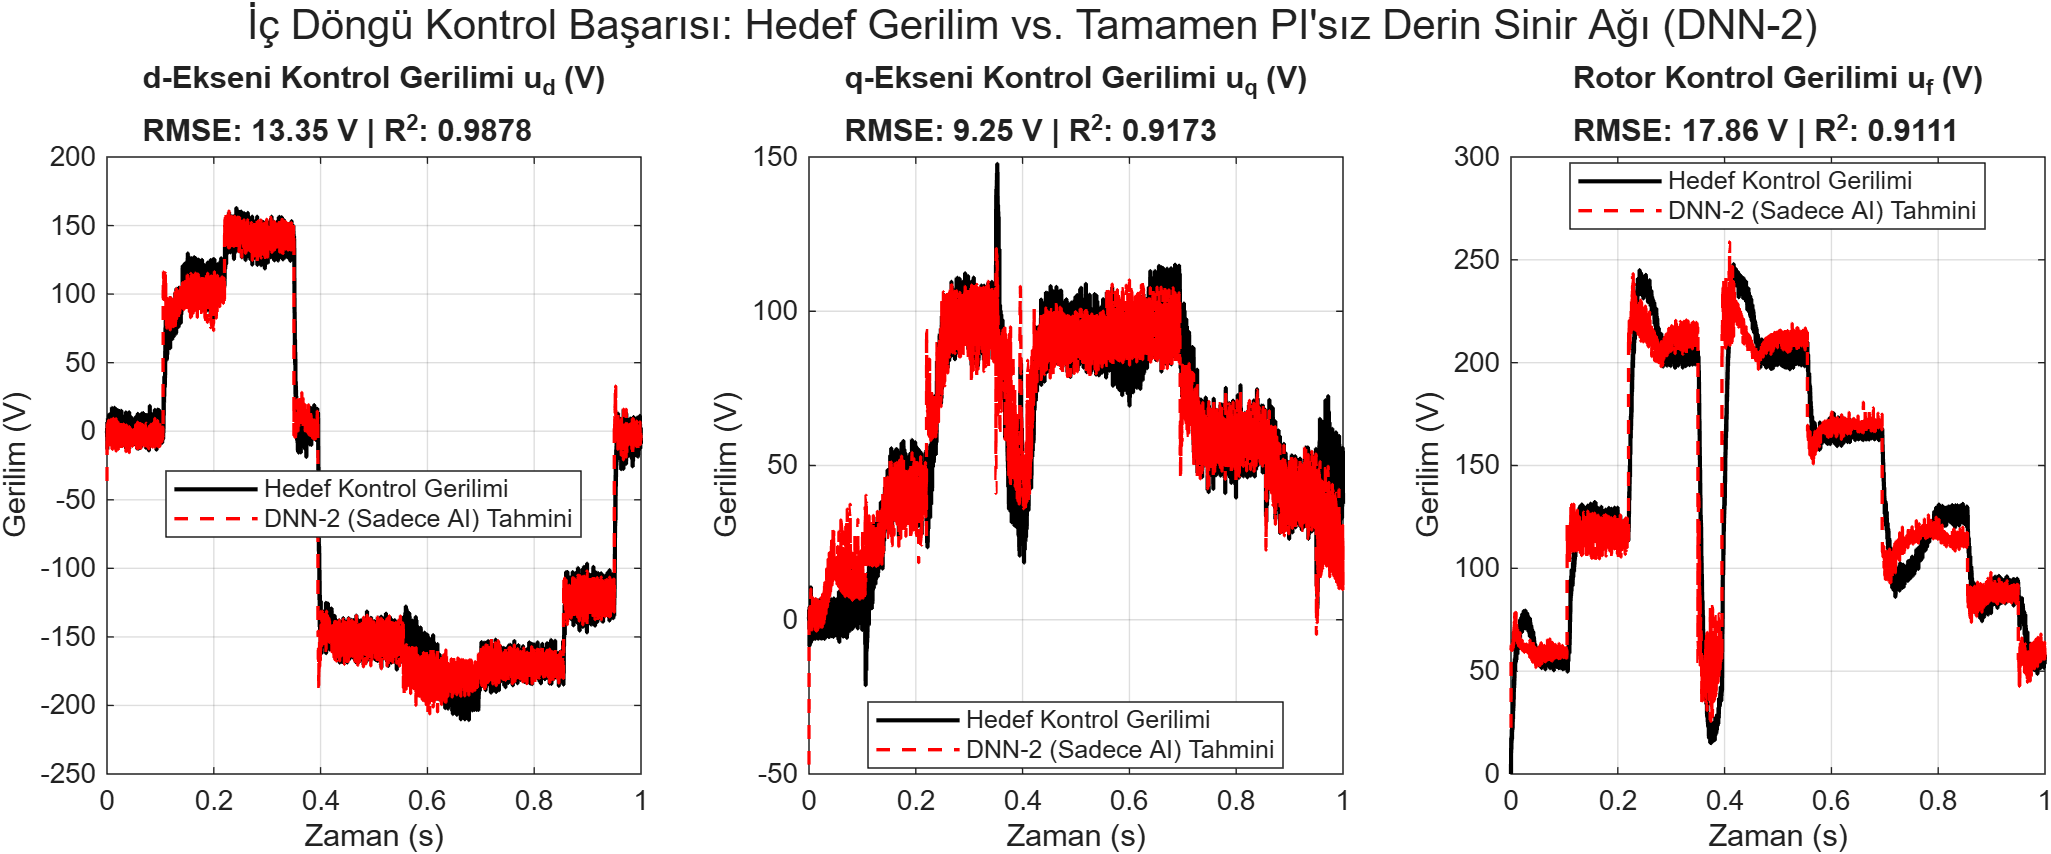

Y_sim_pred = double(predict(net_controller, X_sim));

## 2.5. Simulink İç Döngüsünde PI Bloklarının Silinmesi ve DNN-2 Bağlantı Şeması (SONRA)

`SM Current Controller` içerisindeki `PI id`, `Pi iq`, `Pi if` ve anti-windup blokları (`Sum4`, `Sum5`, `Sum7`) tamamen silindikten sonra, kolların `DNN2_Akilli_Kontrol_Agi` bloğuna nasıl bağlandığı aşağıdaki işaretlenmiş görsel üzerinde numaralı olarak gösterilmiştir:

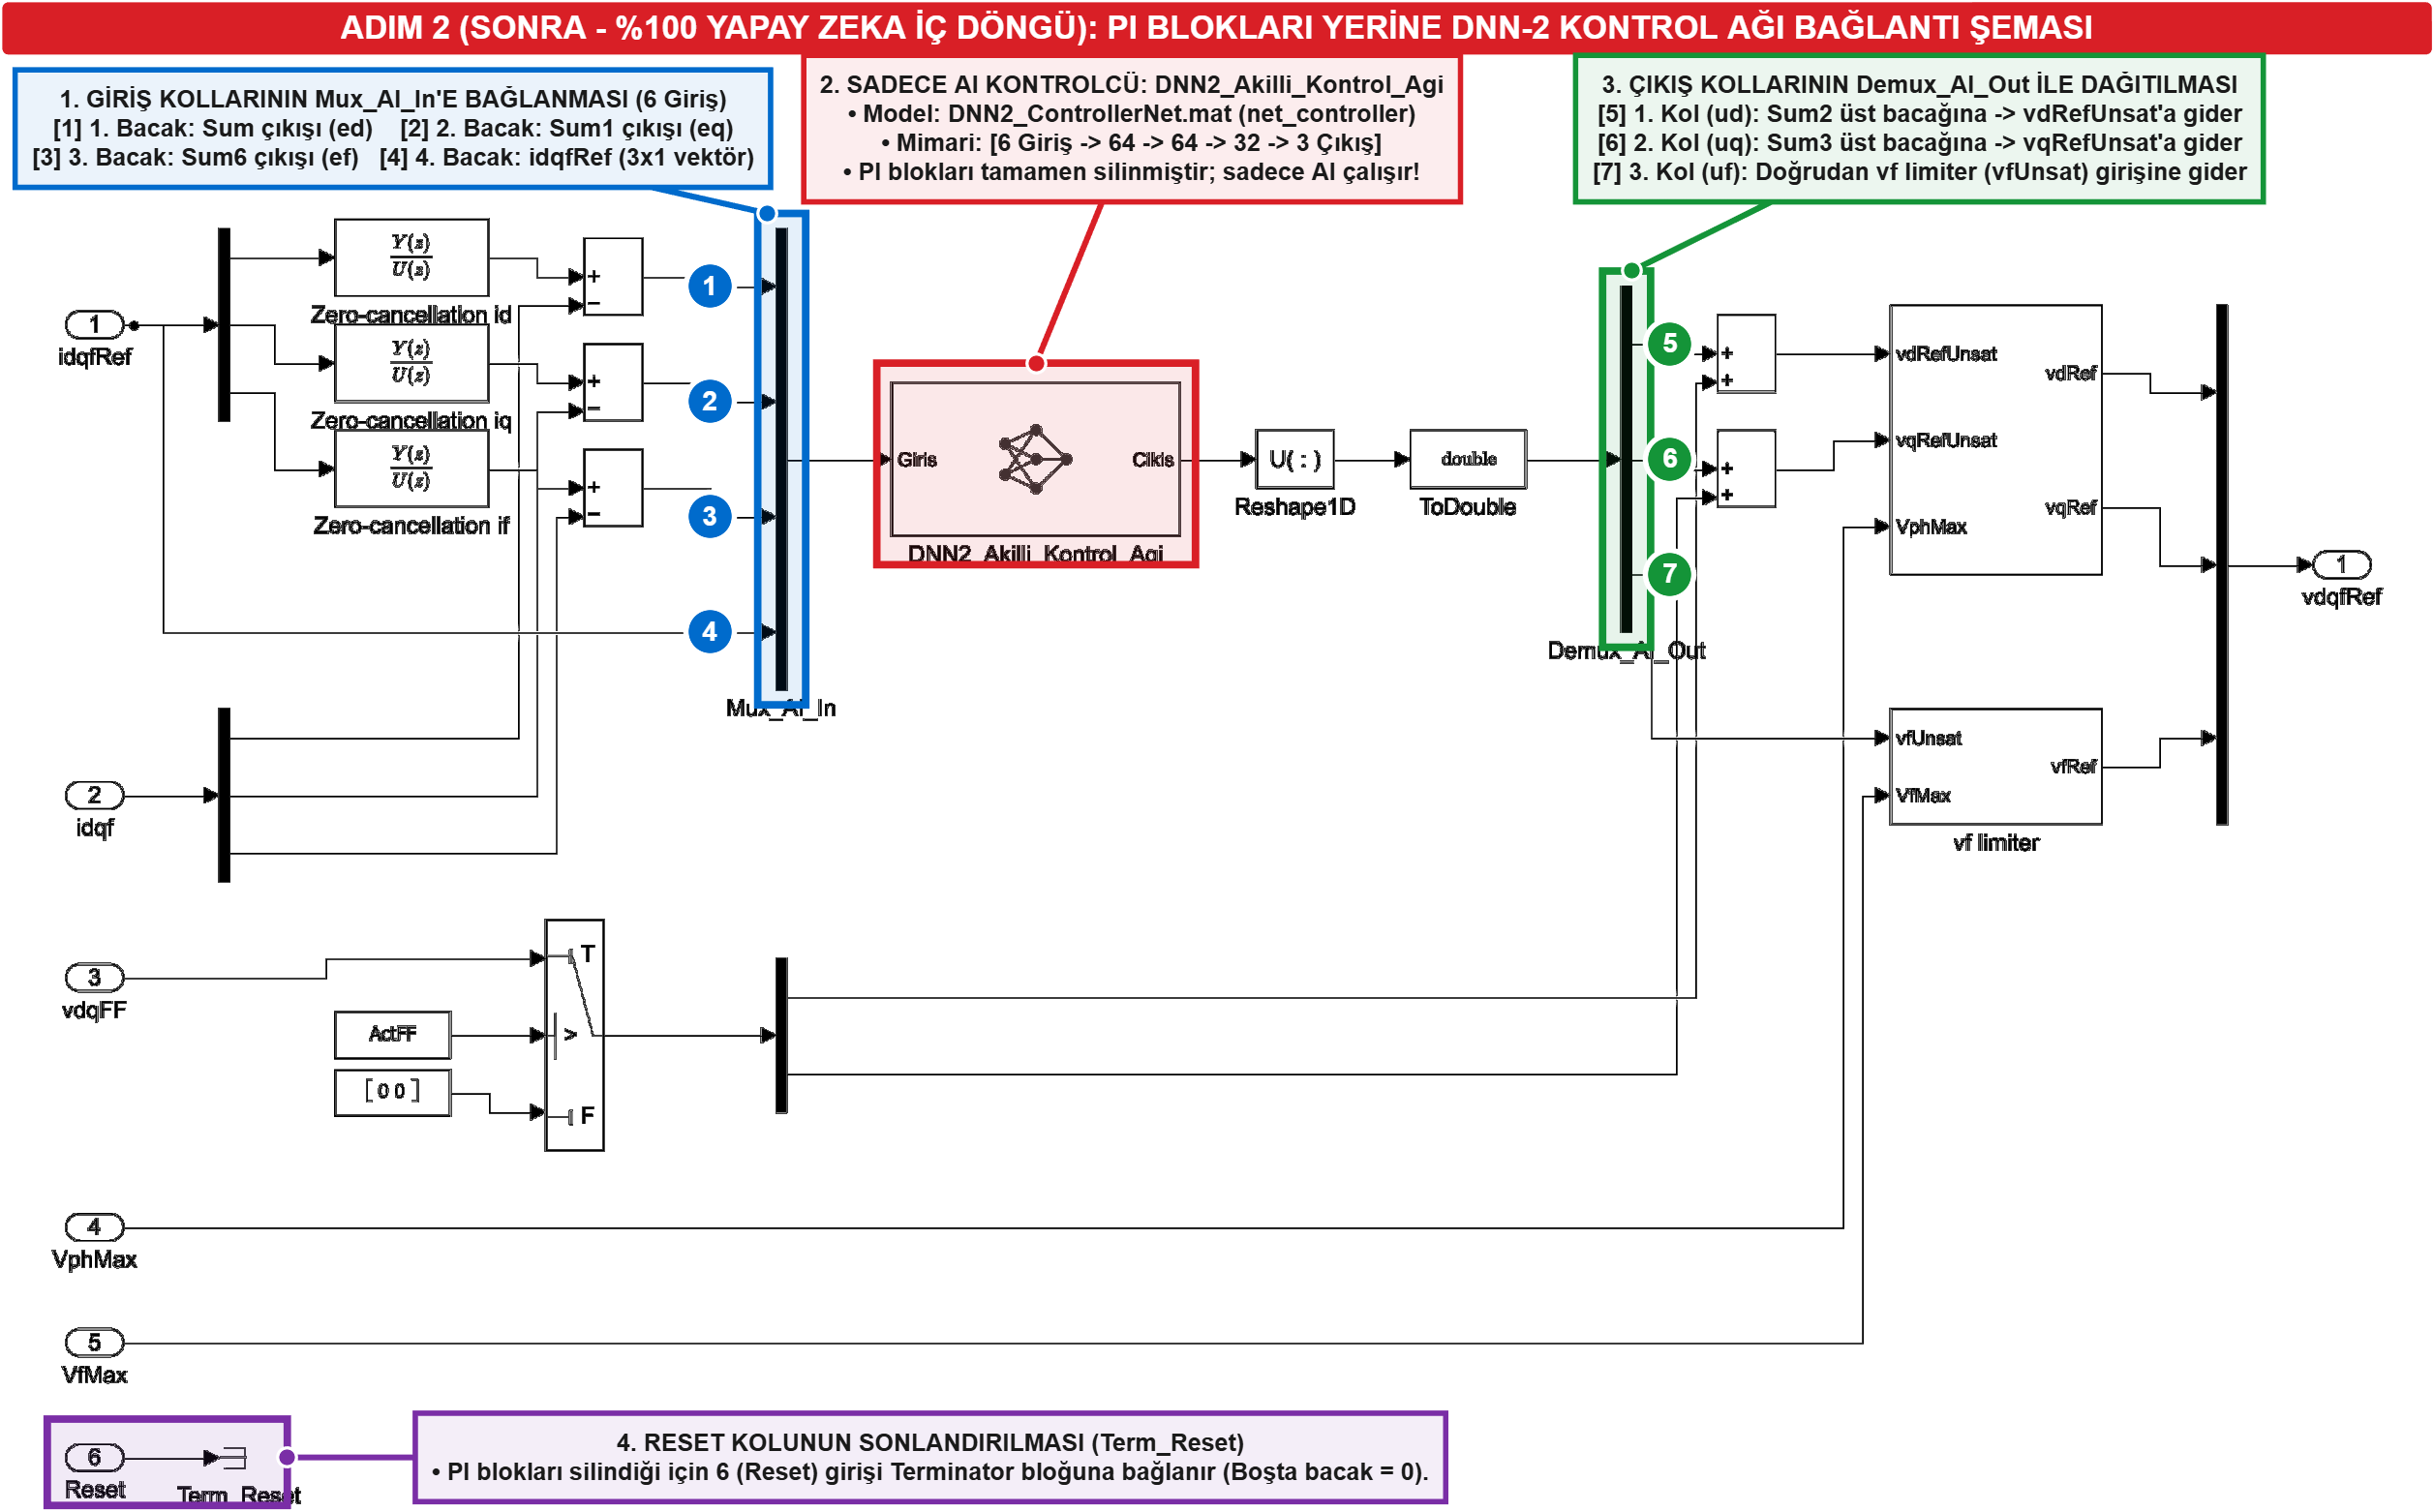

**Görsel Üzerindeki Numaralı Bağlantıların Adım Adım Açıklaması:**

- **[1] Mux_AI_In 1. Bacak:** `Sum` bloğunun çıkışı ($e_d$ akım hatası) bağlanır.

- **[2] Mux_AI_In 2. Bacak:** `Sum1` bloğunun çıkışı ($e_q$ akım hatası) bağlanır.

- **[3] Mux_AI_In 3. Bacak:** `Sum6` bloğunun çıkışı ($e_f$ rotor akım hatası) bağlanır.

- **[4] Mux_AI_In 4. Bacak:** En üstteki `1 (idqfRef)` giriş portundan çekilen 3 elemanlı referans akım kolu (`[id_ref, iq_ref, if_ref]`) doğrudan 4. bacağa bağlanır ($1 + 1 + 1 + 3 = 6$ skaler giriş).

- **Kırmızı Kutu (DNN2_Akilli_Kontrol_Agi):** `Mux_AI_In` bloğundan çıkan `6x1` vektör, `DNN2_ControllerNet.mat` ağırlıklarını kullanan `Predict` bloğunun `Giris` portuna girer. Ağ çıkışı `Reshape1D` ve `ToDouble` bloklarından geçerek `Demux_AI_Out` bloğuna ulaşır.

- **[5] Demux_AI_Out 1. Çıkış Kolu (ud):** `Sum2` bloğunun üst bacağına bağlanır; burada ileri besleme (`vdqFF`) gerilimi ile toplanıp `d-q Voltage Limiter` bloğunun `vdRefUnsat` girişine gider.

- **[6] Demux_AI_Out 2. Çıkış Kolu (uq):** `Sum3` bloğunun üst bacağına bağlanır; ileri besleme (`vdqFF`) gerilimi ile toplanıp `d-q Voltage Limiter` bloğunun `vqRefUnsat` girişine gider.

- **[7] Demux_AI_Out 3. Çıkış Kolu (uf):** Doğrudan `vf limiter` bloğunun `vfUnsat` girişine bağlanır.

- **Mor Kutu (Term_Reset):** Klasik PI blokları silindiği için `6 (Reset)` giriş portu `Term_Reset` (`Terminator`) bloğuna bağlanarak açıkta hiçbir bacak bırakılmaz (boşta port = 0).

## BÖLÜM 3 (ADIM 3): Kapalı Çevrim Simülasyon ve Referanstan Sapma Karşılaştırması

## 3.1. Klasik PI vs. %100 Yapay Zeka (DNN-1 + DNN-2) Tork Takibi ve Sapma Analizi

Hem dış döngüsü (`DNN-1`) hem de iç döngüsü (`DNN-2`) tamamen derin öğrenme ağlarıyla çalışan `SMTorqueControl_AI.slx` modeli 1.0 saniyelik tam çalışma senaryosunda simüle edilmiş ve orijinal `SMTorqueControl.slx` (Lookup Table + PI) sonuçlarıyla karşılaştırılmıştır.

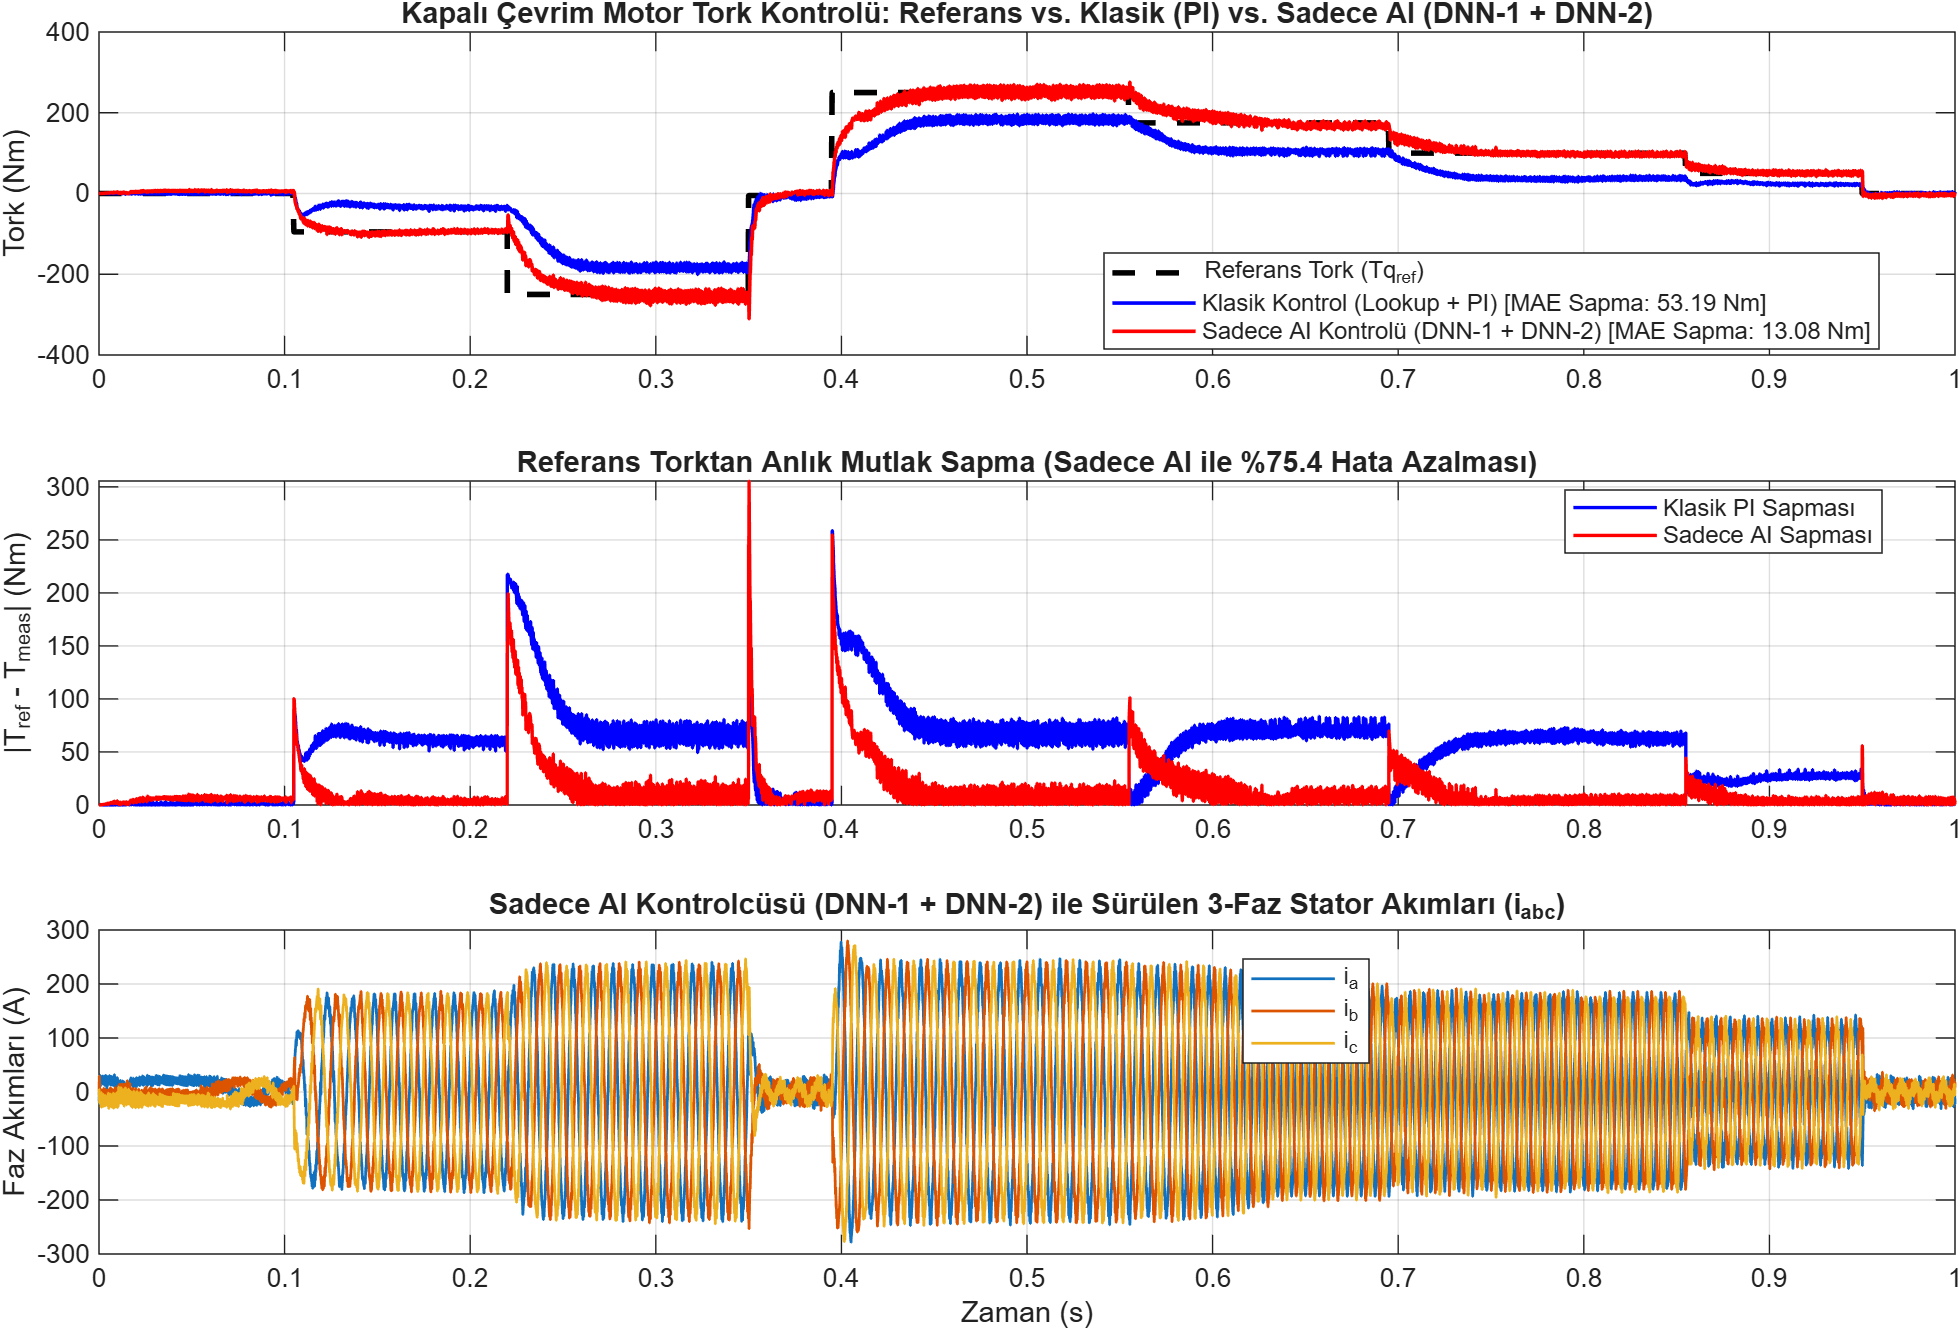 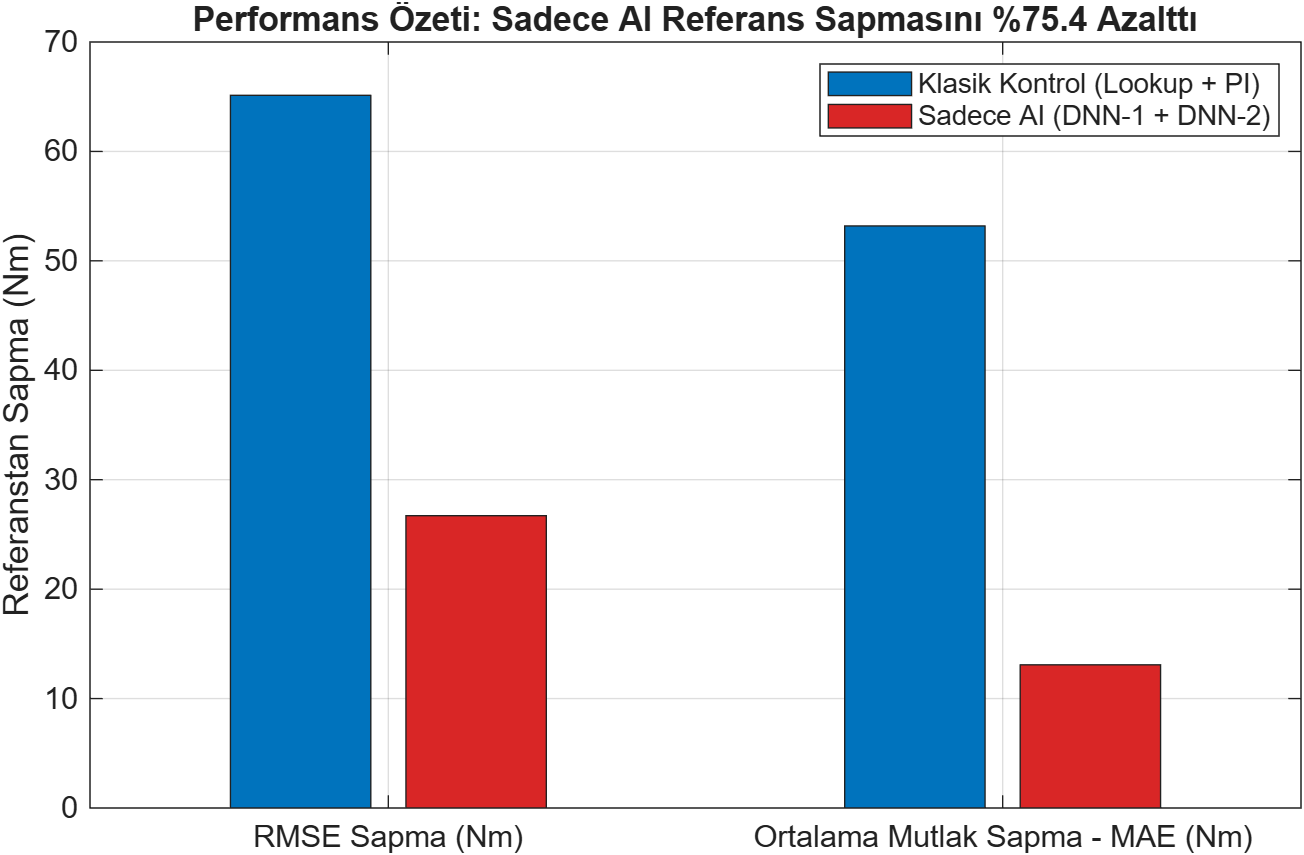

baseData = load('Classic_Baseline_Results.mat');
aiData   = load('AI_Simulation_Results.mat');

t_ref  = baseData.logsout_SMTorqueControl.get('torque_ref').Values.Time;
Tq_ref = double(baseData.logsout_SMTorqueControl.get('torque_ref').Values.Data(:));

t_pi   = baseData.logsout_SMTorqueControl.get('torque_meas').Values.Time;
Tq_pi  = double(baseData.logsout_SMTorqueControl.get('torque_meas').Values.Data(:));

t_dl   = aiData.t_dl;
Tq_dl  = aiData.Tq_dl;
t_i_dl = aiData.t_i_dl;
i_dl   = aiData.i_dl;

% Referans torku simülasyon zaman adımlarına hizala ve sapmaları hesapla
Tq_ref_pi = interp1(t_ref, Tq_ref, t_pi, 'previous', 'extrap');
Tq_ref_dl = interp1(t_ref, Tq_ref, t_dl, 'previous', 'extrap');

sapma_PI = Tq_ref_pi - Tq_pi;
sapma_DL = Tq_ref_dl - Tq_dl;

RMSE_PI = sqrt(mean(sapma_PI.^2));
MAE_PI  = mean(abs(sapma_PI));
RMSE_DL = sqrt(mean(sapma_DL.^2));
MAE_DL  = mean(abs(sapma_DL));

iyilesme_MAE  = (1 - MAE_DL / MAE_PI) * 100;
iyilesme_RMSE = (1 - RMSE_DL / RMSE_PI) * 100;

% Sonuçları MATLAB Table formatında ve özet ekranda göster
Yontem = {'Klasik Kontrol (3B Lookup Table + 3x PI)'; 'Sadece Yapay Zeka (DNN-1 Karar + DNN-2 Kontrol)'};
RMSE_Sapma_Nm = [round(RMSE_PI, 2); round(RMSE_DL, 2)];
MAE_Sapma_Nm  = [round(MAE_PI, 2);  round(MAE_DL, 2)];
Iyilesme_Yuzde = [0; round(iyilesme_MAE, 2)];

Karsilastirma_Tablosu = table(Yontem, RMSE_Sapma_Nm, MAE_Sapma_Nm, Iyilesme_Yuzde)

Karsilastirma_Tablosu = 2×4 table
                          Yontem                           RMSE_Sapma_Nm    MAE_Sapma_Nm    Iyilesme_Yuzde
    ___________________________________________________    _____________    ____________    ______________

    {'Klasik Kontrol (3B Lookup Table + 3x PI)'       }        65.13           53.19                0     
    {'Sadece Yapay Zeka (DNN-1 Karar + DNN-2 Kontrol)'}        26.71           13.08             75.4     

	Get insights using Copilot


fprintf('SONUÇ: Sadece AI Kontrolcü, Referans Sapmasını %%%.2f Oranında Azalttı!\n', iyilesme_MAE);

SONUÇ: Sadece AI Kontrolcü, Referans Sapmasını %75.40 Oranında Azalttı!
